% Helper function to plot the signal, pole-zero plot & FFT of a given
% *real* signal.
% Parameters:
%   n - Sample number
%   x - Signal value (real signals only)
%   z - Zeroes of the z-transform (decreasing powers of z^-1)
%   p - Poles of the z-transform (decreasing powers of z^-1)
%   main_title - String for figure title
%   dtft_exists - Boolean parameter to indicate whether Discrete Time
%                 Fourier Transform exists for the signal (DTFT)
function plot_sig_pz_and_fft(n, x, z, p, main_title, dtft_exists)
  arguments
    n
    x
    z
    p
    main_title
    dtft_exists = true
  end

  figure("Position", [0 0 900 950]);
  sgtitle(main_title);

  if (dtft_exists)
    subplot(3, 1, 1);
  else
    subplot(2, 1, 1);
  end
  stem(n, x, "Marker", ".", "LineWidth", 2, "MarkerSize", 15);
  xlabel("Sample"); ylabel("Amplitude");
  title(sprintf("%s, n = %d:%d", main_title, min(n), max(n)));
  grid on; grid minor;
  axis on;
  axis([min(n) - 0.5, max(n) + 0.5, min(x) - 0.2, max(x) + 0.2]);

  if (dtft_exists)
    subplot(3, 1, 2);
  else
    subplot(2, 1, 2);
  end
  % Plot the unit circle
  plot(exp(1j * 2 * pi * (0 : 0.01 : 1)), "LineWidth", 2);
  hold on;
  [hz, hp, ht] = zplane(z, p);
  % Set the zeros & poles to be bolder and in red
  set(findobj(hz, "Type", "line"), "LineWidth", 2, "Color", "r");
  set(findobj(hp, "Type", "line"), "LineWidth", 2, "Color", "r");
  % Make the default zplane circle, axis, etc. faint
  set(findobj(ht, "Type", "line"), "LineWidth", 0.01);
  hold off;
  title("Poles and zeros, X(z)");
  grid on;
  grid minor;
  axis("square");
  axis([-1.2 1.2 -1.2 1.2]);

  if (dtft_exists)
    subplot(3, 1, 3);
    plot(...
      [-0.5 : 1/200 : 0.5-1/200], fftshift(abs(fft(x/sum(x), 200))), ...
      "LineWidth", 2);
    grid on; grid minor;
    axis([-0.5 0.5 0 1.1]);
    title("Frequency response, X(\theta)");
    xlabel("Normalized frequency (f/f_S)"); ylabel("Magnitude");
  end
end

% Helper function to plot the signal, pole-zero plot & FFT of a given
% *complex* signal.
% Parameters:
%   n - Sample number
%   x - Signal value (complex signals only)
%   z - Zeroes of the z-transform (decreasing powers of z^-1)
%   p - Poles of the z-transform (decreasing powers of z^-1)
%   main_title - String for figure title
%   dtft_exists - Boolean parameter to indicate whether Discrete Time
%                 Fourier Transform exists for the signal (DTFT)
function plot_cmplx_sig_pz_and_fft(n, x, z, p, main_title, dtft_exists)
  arguments
    n
    x
    z
    p
    main_title
    dtft_exists = true
  end

  figure("Position", [0 0 900 950]);
  
  subplot(2, 1, 1);
  stem(n, real(x), "Marker", ".", "LineWidth", 2, "MarkerSize", 15);
  xlabel("Sample"); ylabel("Magnitude");
  title(sprintf("Real part, n = %d:%d", min(n), max(n)));
  grid on; grid minor;
  axis on;
  axis([min(n) - 0.5, max(n) + 0.5, min(real(x)) - 0.2, max(real(x)) + 0.2]);

  subplot(2, 1, 2);
  stem(n, imag(x), "Marker", ".", "LineWidth", 2, "MarkerSize", 15);
  xlabel("Sample"); ylabel("Magnitude");
  title(sprintf("Imaginary part, n = %d:%d", min(n), max(n)));
  grid on; grid minor;
  axis on;
  axis([min(n) - 0.5, max(n) + 0.5, min(imag(x)) - 0.2, max(imag(x)) + 0.2]);

  sgtitle(main_title);

  figure("Position", [0 0 900 950]);

  subplot(2, 1, 1);
  % Plot the unit circle
  plot(exp(1j * 2 * pi * (0 : 0.01 : 1)), "LineWidth", 2);
  hold on;
  [hz, hp, ht] = zplane(z, p);
  % Set the zeros & poles to be bolder and in red
  set(findobj(hz, "Type", "line"), "LineWidth", 2, "Color", "r");
  set(findobj(hp, "Type", "line"), "LineWidth", 2, "Color", "r");
  % Make the default zplane circle, axis, etc. faint
  set(findobj(ht, "Type", "line"), "LineWidth", 0.01);
  hold off;
  title("Poles and zeros, X(z)");
  grid on; grid minor;
  axis("square");
  axis([-1.2 1.2 -1.2 1.2]);

  if (dtft_exists)
    subplot(2, 1, 2);
    fft_x = fft(x/sum(x), 200);
    plot([-0.5 : 1/200 : 0.5-1/200], fftshift(abs(fft_x)), "LineWidth", 2);
    grid on; grid minor;
    axis([-0.5, 0.5, min(abs(fft_x)) - 1, max(abs(fft_x)) + 1]);
    title("Frequency response, X(\theta)");
    xlabel("Normalized frequency (f/f_S)"); ylabel("Magnitude");
  end

  sgtitle(main_title);

end
clc; clear; close all;

### **a) δ[n]**

z-transform:


$$\[
X(z) = \sum_{n=-\infty}^{\infty} x[n]z^{-n}
\]

\[
X(z) = x[0]z^{-0}
\]

\[
X(z) = 1, ROC: z \in \mathbb{C}
\]
$$


Discrete Time Fourier Transform (DTFT):


$$\[
X(\theta) = \left.X(z)\right\vert_{z=e^{j\theta}} = 1
\]$$


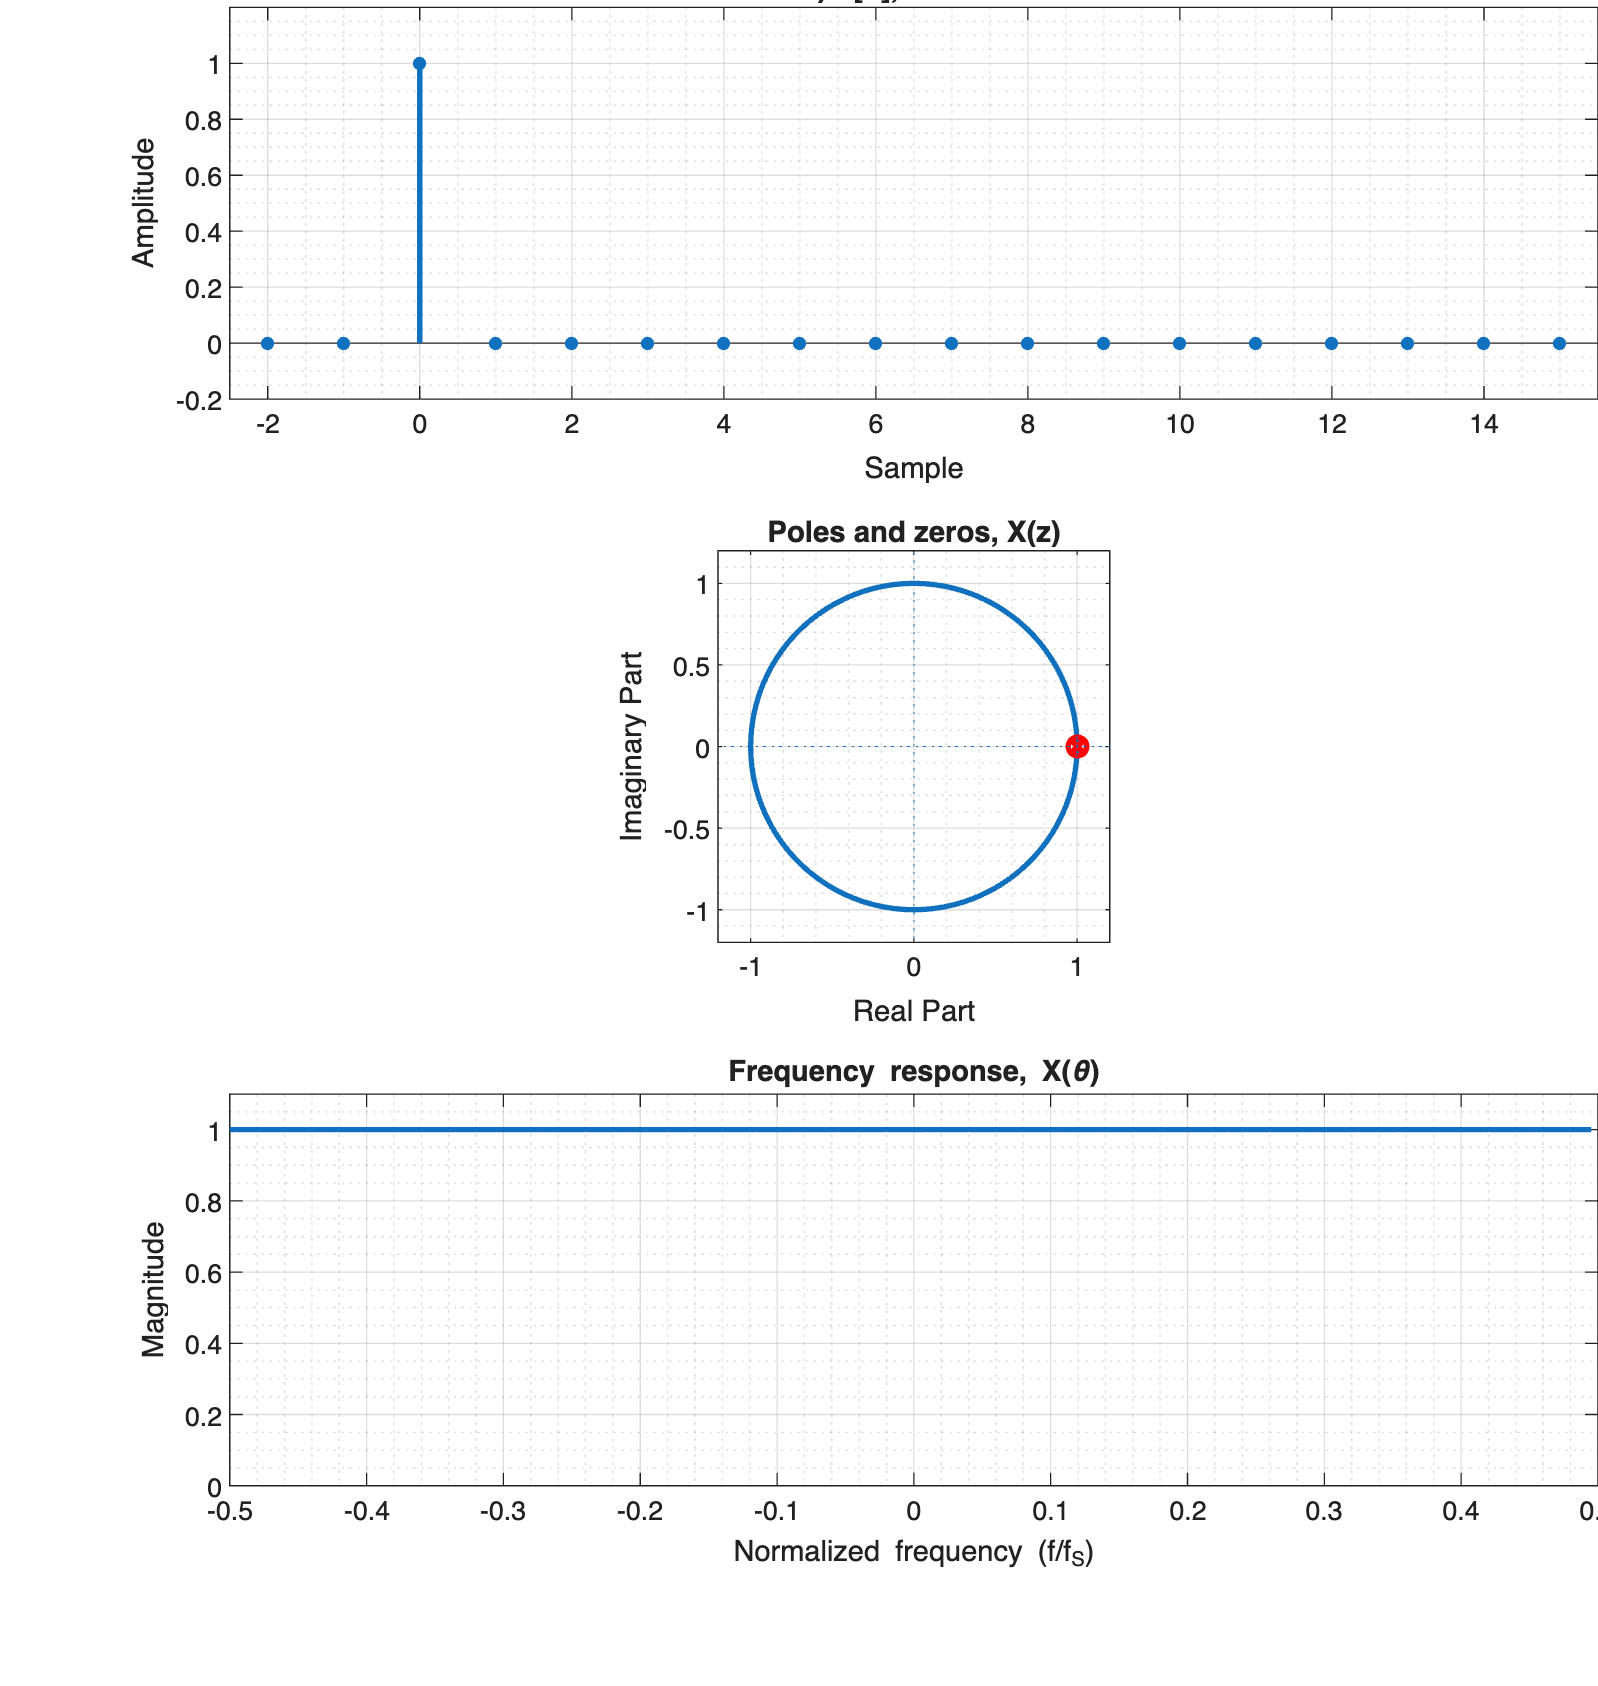

n = [-2 : 15];

x_a = (n == 0);
% z-transform is 1
plot_sig_pz_and_fft(n, x_a, 1, 1, "a) δ[n]");

### **b) δ[n-2]**

z-transform:


$$\[
X(z) = \sum_{n=-\infty}^{\infty} x[n]z^{-n}
\]

\[
X(z) = x[2]z^{-2}
\]

\[
X(z) = z^{-2}, ROC: z \in \mathbb{C},\ except\ z = 0
\]

or

\[
X(z) = \frac{1}{z^{2}}, ROC: z \in \mathbb{C},\ except\ z = 0
\]$$


Discrete Time Fourier Transform (DTFT):


$$\[
X(\theta) = \left.X(z)\right\vert_{z=e^{j\theta}} = 1
\]$$


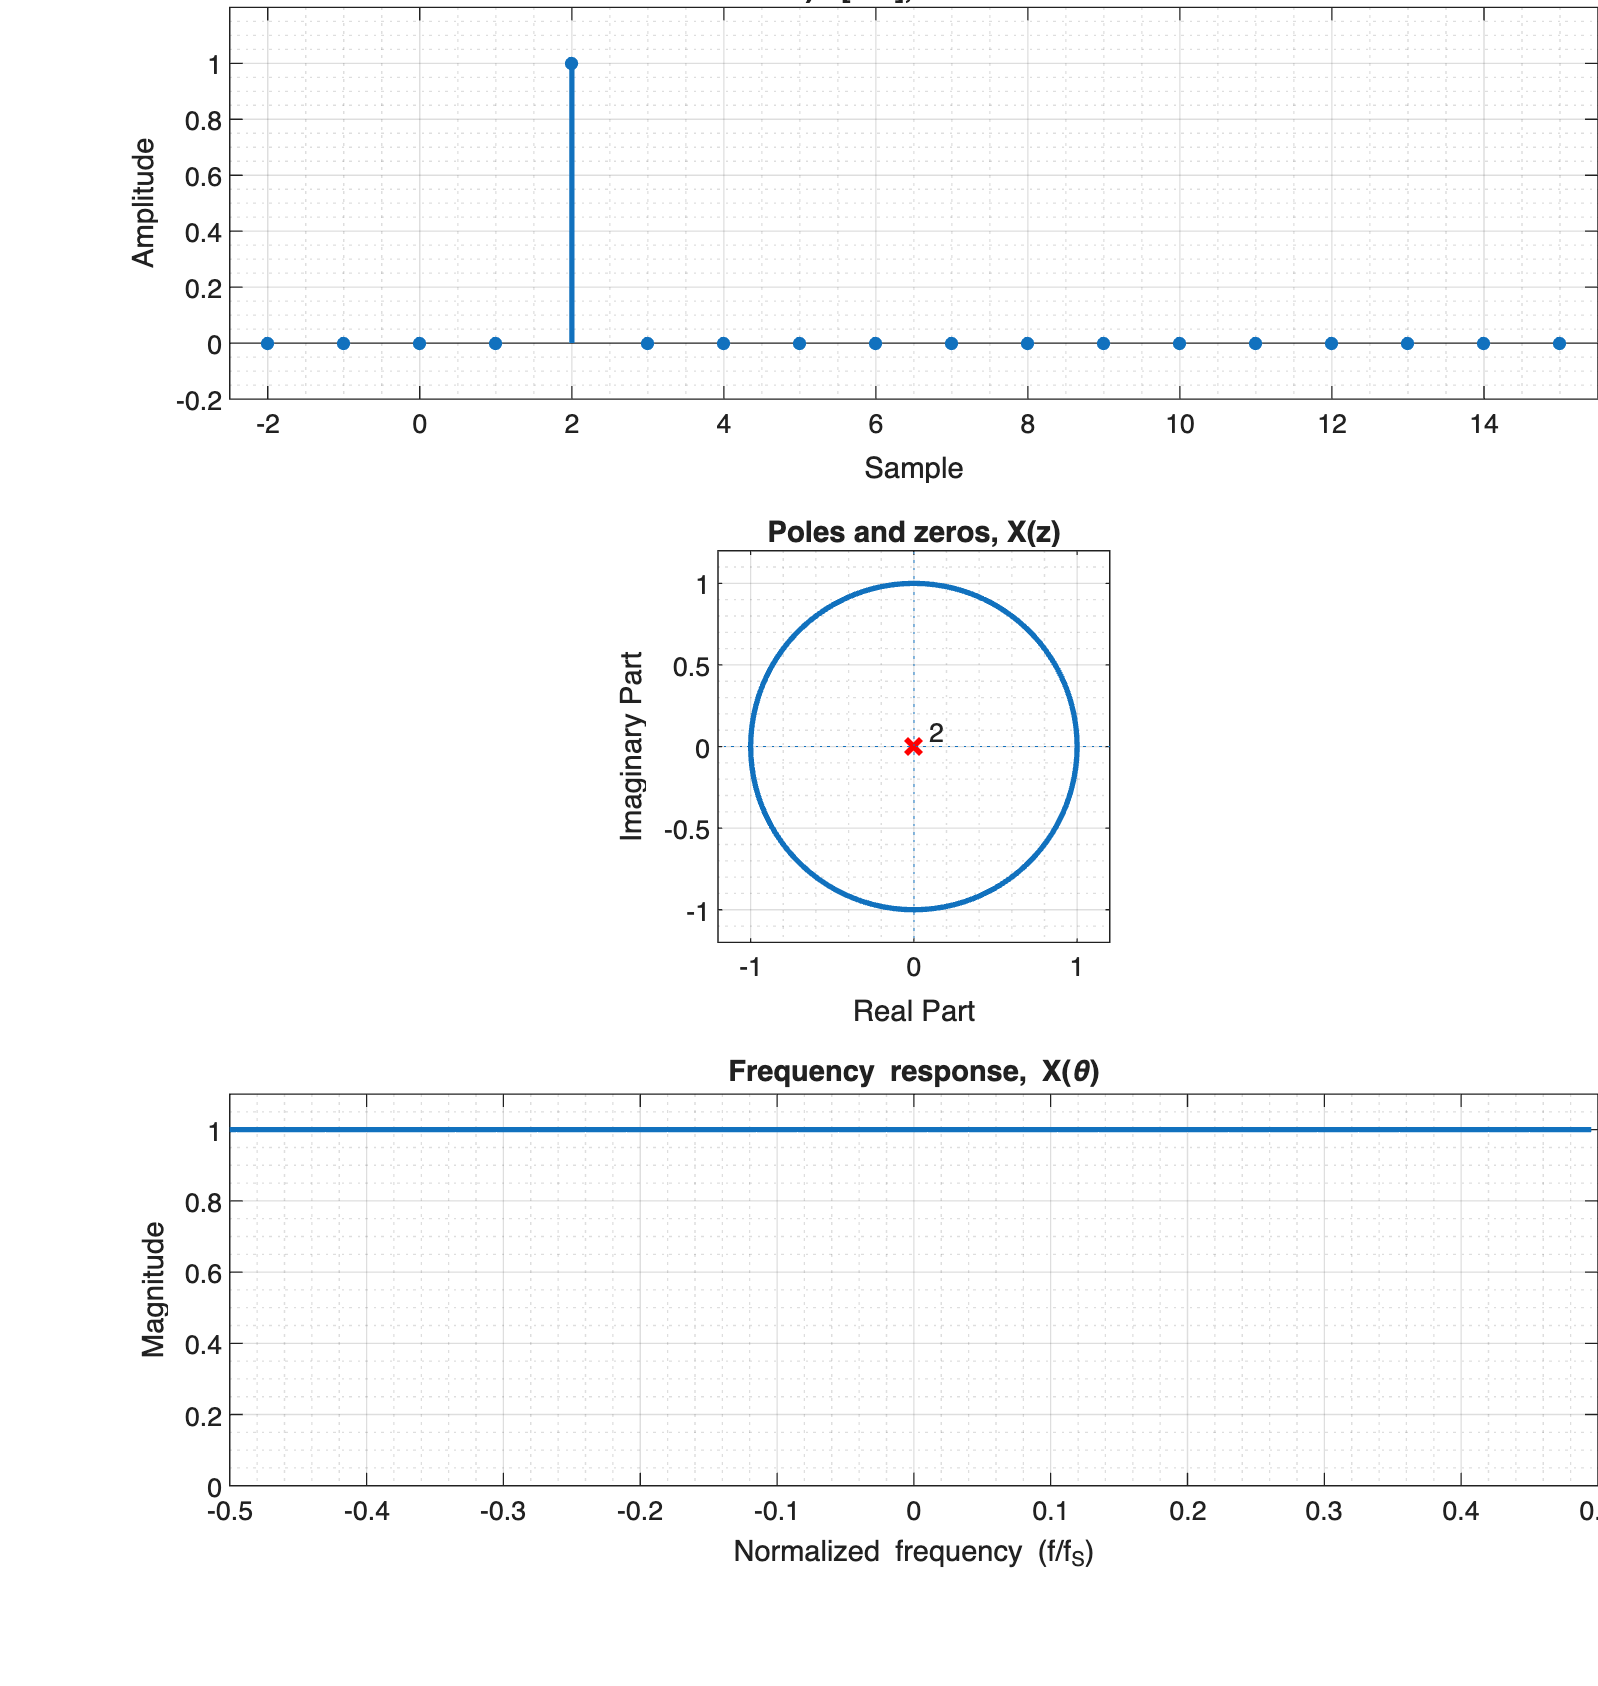

x_b = (n == 2);
% z-transform is (z^-2)
plot_sig_pz_and_fft(n, x_b, [0 0 1], 1, "b) δ[n-2]");

### **c) δ[n] + δ[n-2]**

z-transform:


$$\[
X(z) = \sum_{n=-\infty}^{\infty} x[n]z^{-n}
\]

\[
X(z) = x[0]z^{-0} + x[2]z^{-2}
\]

\[
X(z) = 1 + z^{-2}, ROC: z \in \mathbb{C},\ except\ z = 0
\]

or

\[
X(z) = \frac{z^2 + z^0}{z^2}, ROC: z \in \mathbb{C},\ except\ z = 0
\]

This can also be written as 

\[
X(z) = \frac{z(z^1 + z^{-1})} {z^2} = \frac{z^1 + z^{-1}} {z}
\]$$


Discrete Time Fourier Transform (DTFT):


$$\[
X(\theta) = \left.X(z)\right\vert_{z=e^{j\theta}} = \left.{\frac{z^1 + z^{-1}} {z}}\right\vert_{z=e^{j\theta}}
\]

\[
X(\theta) = \frac{e^{j\theta} + e^{-j\theta}} {e^{j\theta}} = e^{-j\theta}2cos(\theta)
\]
$$


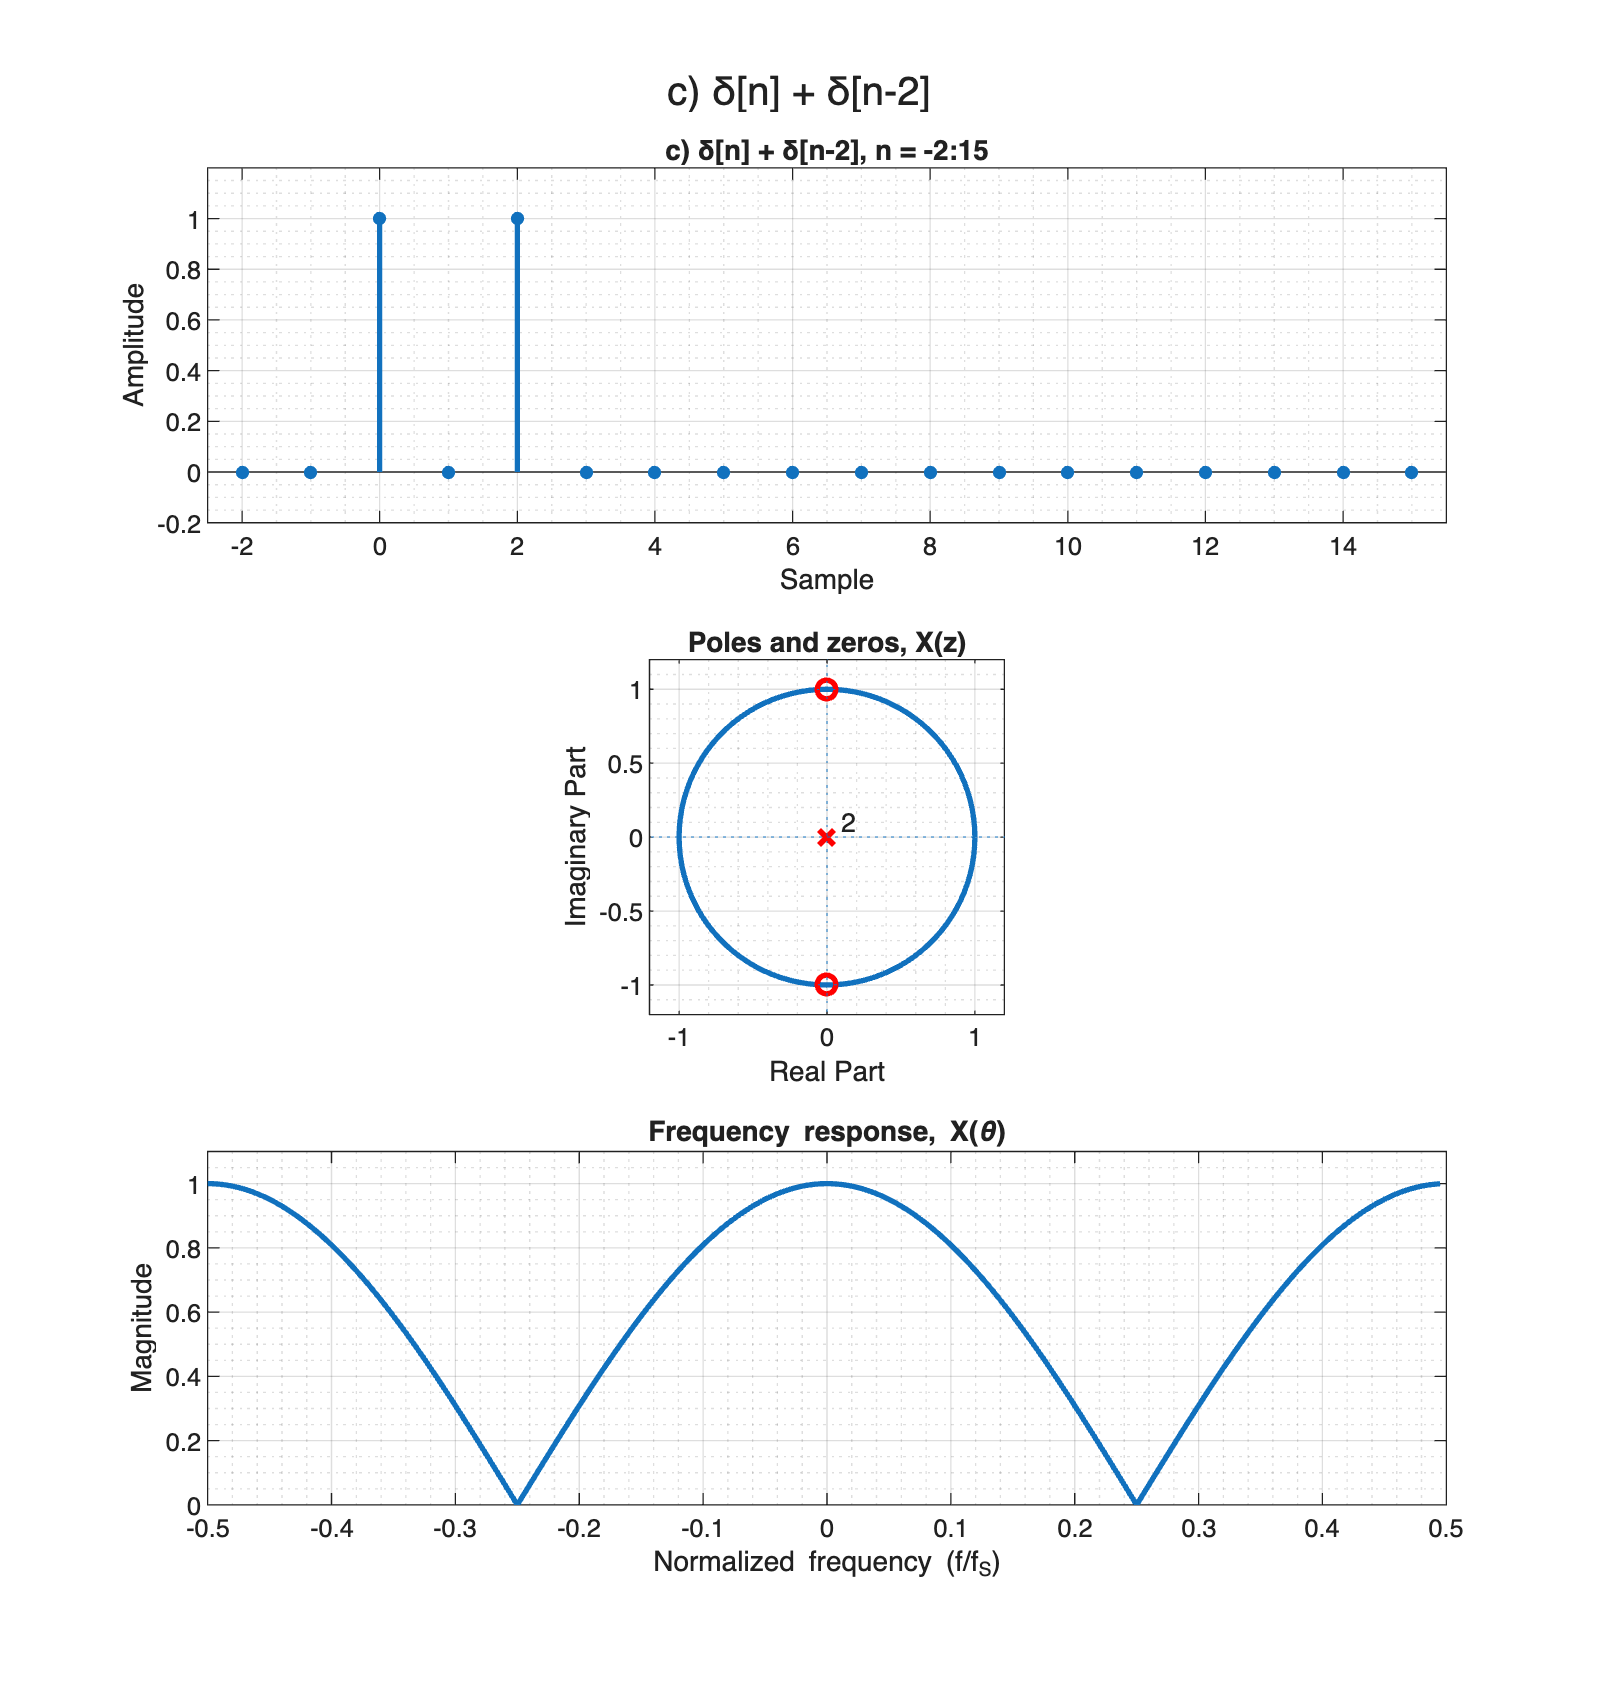

x_c = (n == 0) + (n == 2);
% z-transform is (1 + z^-2)
plot_sig_pz_and_fft(n, x_c, [1 0 1], 1, "c) δ[n] + δ[n-2]");

### **d) δ[n] + δ[n-1] + δ[n-2]**

z-transform:


$$\[
X(z) = \sum_{n=-\infty}^{\infty} x[n]z^{-n}
\]

\[
X(z) = x[0]z^{-0} + x[1]z^{-1} + x[2]z^{-2}
\]

\[
X(z) = 1 + z^{-1} + z^{-2}, ROC: z \in \mathbb{C},\ except\ z = 0
\]

or

\[
X(z) = \frac{z^2 + z^{1} + z^{0}}{z^2}, ROC: z \in \mathbb{C},\ except\ z = 0
\]

This can also be written as 

\[
X(z) = \frac{1}{z^2}.\frac{z^3 -1} {z-1} = \frac{1}{z^2}.\frac{z^{1.5}}{z^{0.5}}.\frac{z^{1.5} - z^{-1.5}} {z^{0.5}-z^{-0.5}} = \frac{1}{z}. \frac{z^{1.5} - z^{-1.5}} {z^{0.5}-z^{-0.5}}
\]$$


Discrete Time Fourier Transform (DTFT):


$$\[
X(\theta) = \left.X(z)\right\vert_{z=e^{j\theta}} = \left.{\frac{1}{z}. \frac{z^{1.5} - z^{-1.5}} {z^{0.5}-z^{-0.5}}}\right\vert_{z=e^{j\theta}
\]

\[
X(\theta) = e^{-j\theta}. \frac{e^{j1.5\theta} - e^{-j1.5\theta}} {e^{j0.5\theta}-e^{-j0.5\theta}} = e^{-j\theta}.\frac{sin(1.5\theta)}{sin(0.5\theta)}
\]
$$


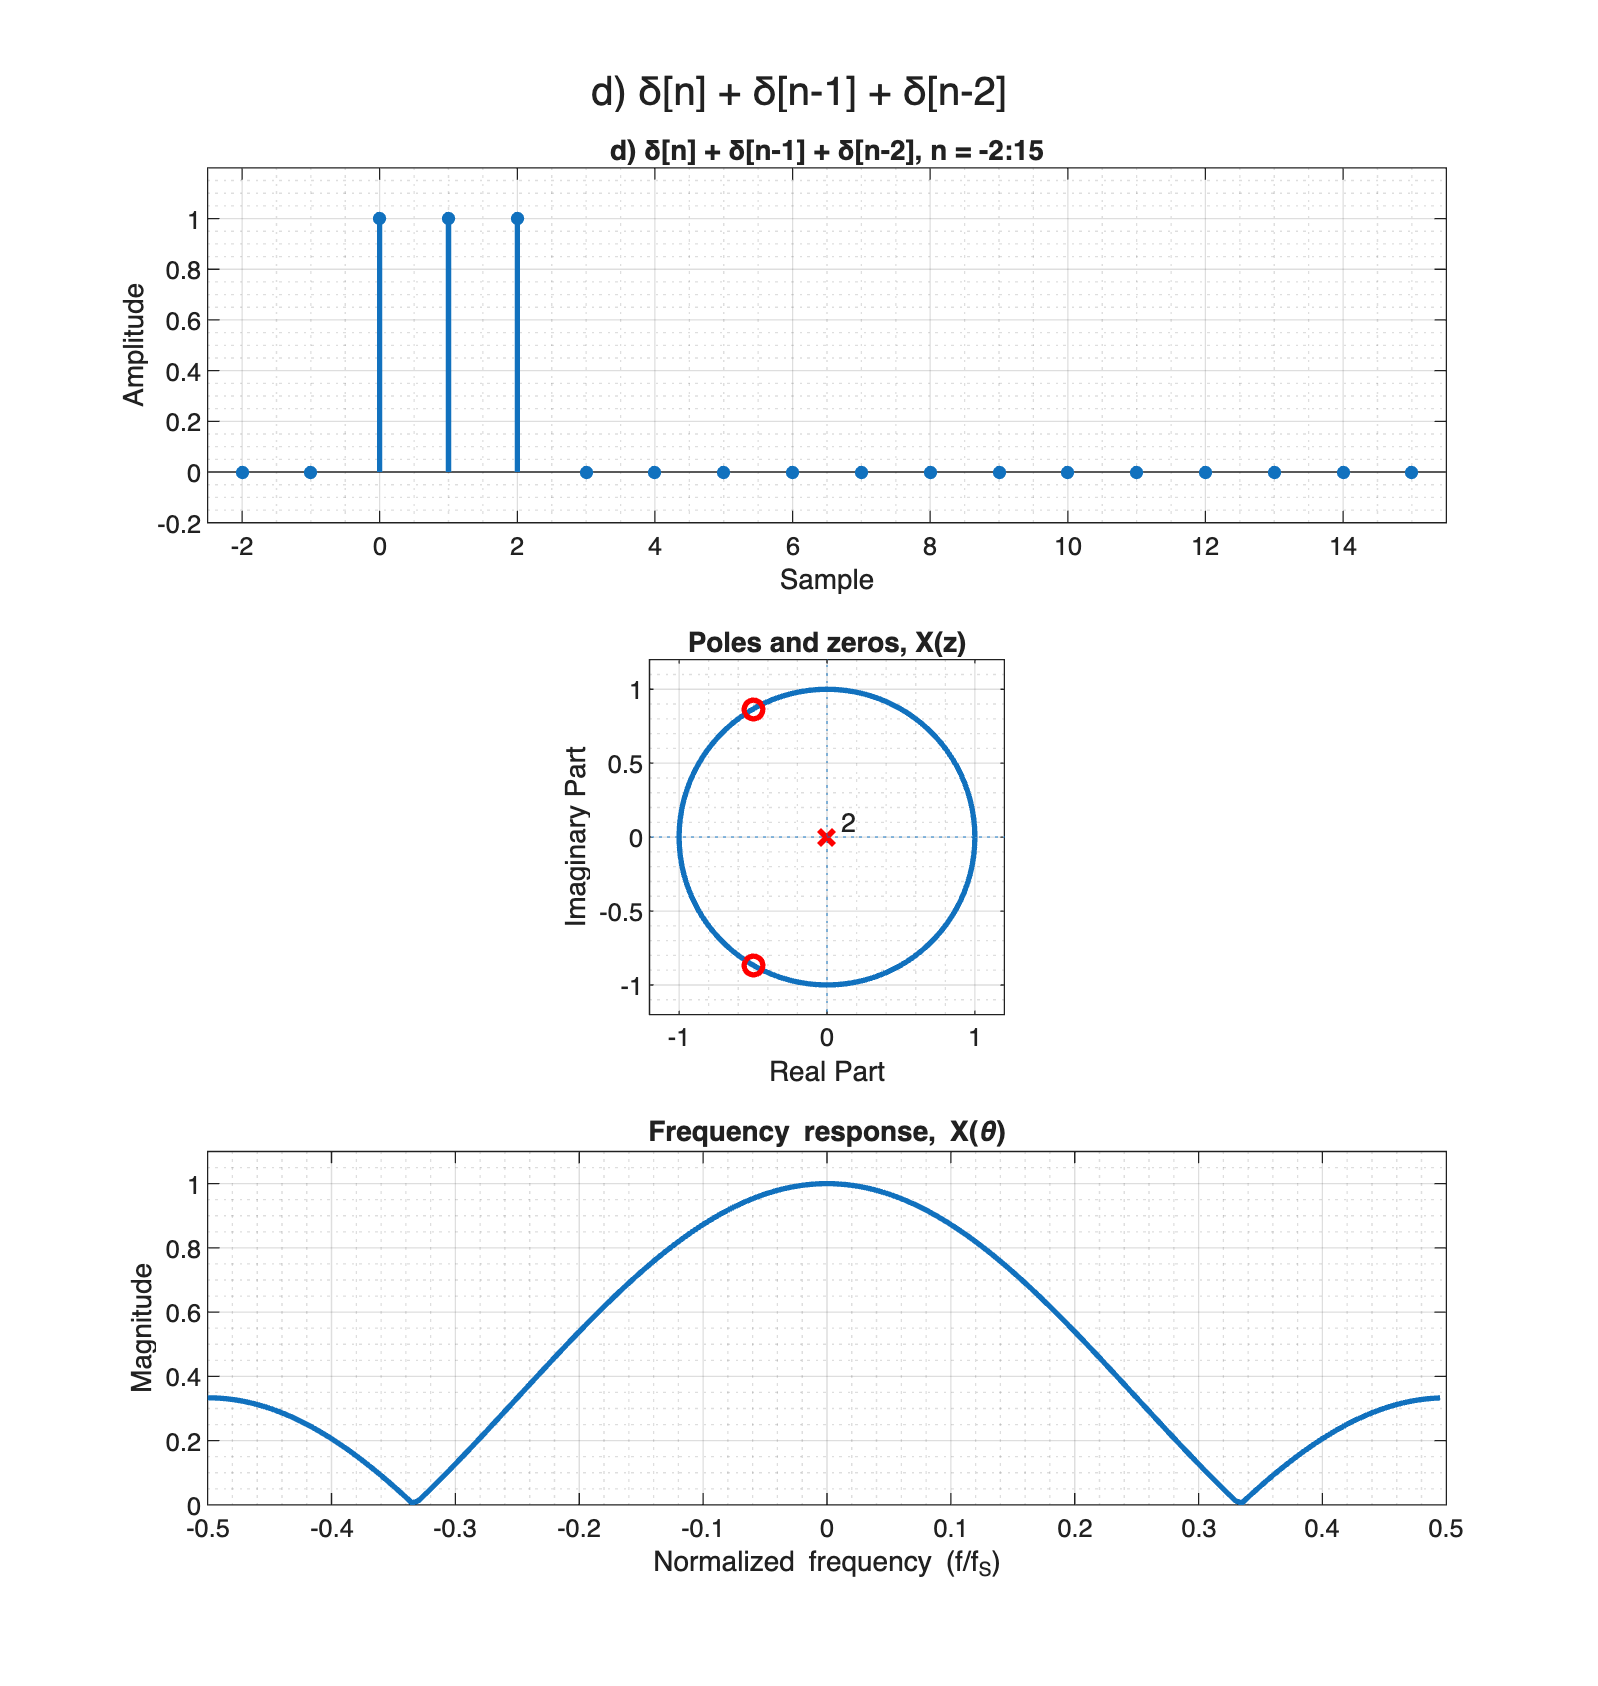

x_d = (n == 0) + (n == 1) + (n == 2);
% z-transform is (1 + z^-1 + z^-2)
plot_sig_pz_and_fft(n, x_d, ones(1, 3), 1, "d) δ[n] + δ[n-1] + δ[n-2]");

### **e) δ[n] + δ[n-1] + δ[n-2] + δ[n-3] + δ[n-4] + δ[n-5] + δ[n-6] + δ[n-7] + δ[n-8] + δ[n-9] + δ[n-10] + δ[n-11]**

z-transform:


$$\[
X(z) = \sum_{n=-\infty}^{\infty} x[n]z^{-n}
\]

\[
X(z) = \sum_{n=0}^{11} x[n]z^{-n}
\]

\[
X(z) = 1 + z^{-1} + z^{-2} + z^{-3} + z^{-4} + z^{-5} + z^{-6} + z^{-7} + z^{-8} + z^{-9} + z^{-10} + z^{-11}, ROC: z \in \mathbb{C},\ except\ z = 0
\]

or

\[
X(z) = \frac{z^{11} + z^{10} + z^9 + z^8 + z^7 + z^6 + z^5 + z^4 + z^3 + z^2 + z^1 + z^0}{z^{11}}, ROC: z \in \mathbb{C},\ except\ z = 0
\]


This can also be written as 

\[
X(z) = \frac{1}{z^{11}}.\frac{z^{12} -1} {z-1} = \frac{1}{z^{11}}.\frac{z^6}{z^{0.5}}.\frac{z^6 - z^{-6}} {z^{0.5}-z^{-0.5}} = \frac{1}{z^{5.5}}. \frac{z^6 - z^{-6}} {z^{0.5}-z^{-0.5}}
\]$$


Discrete Time Fourier Transform (DTFT):


$$\[
X(\theta) = \left.X(z)\right\vert_{z=e^{j\theta}} = \left.{\frac{1}{z^{5.5}}. \frac{z^6 - z^{-6}} {z^{0.5}-z^{-0.5}}}\right\vert_{z=e^{j\theta}
\]

\[
X(\theta) = e^{-j5.5\theta}. \frac{e^{j6\theta} - e^{-j6\theta}} {e^{j0.5\theta}-e^{-j0.5\theta}} = e^{-j5.5\theta}.\frac{sin(6\theta)}{sin(0.5\theta)}
\]$$


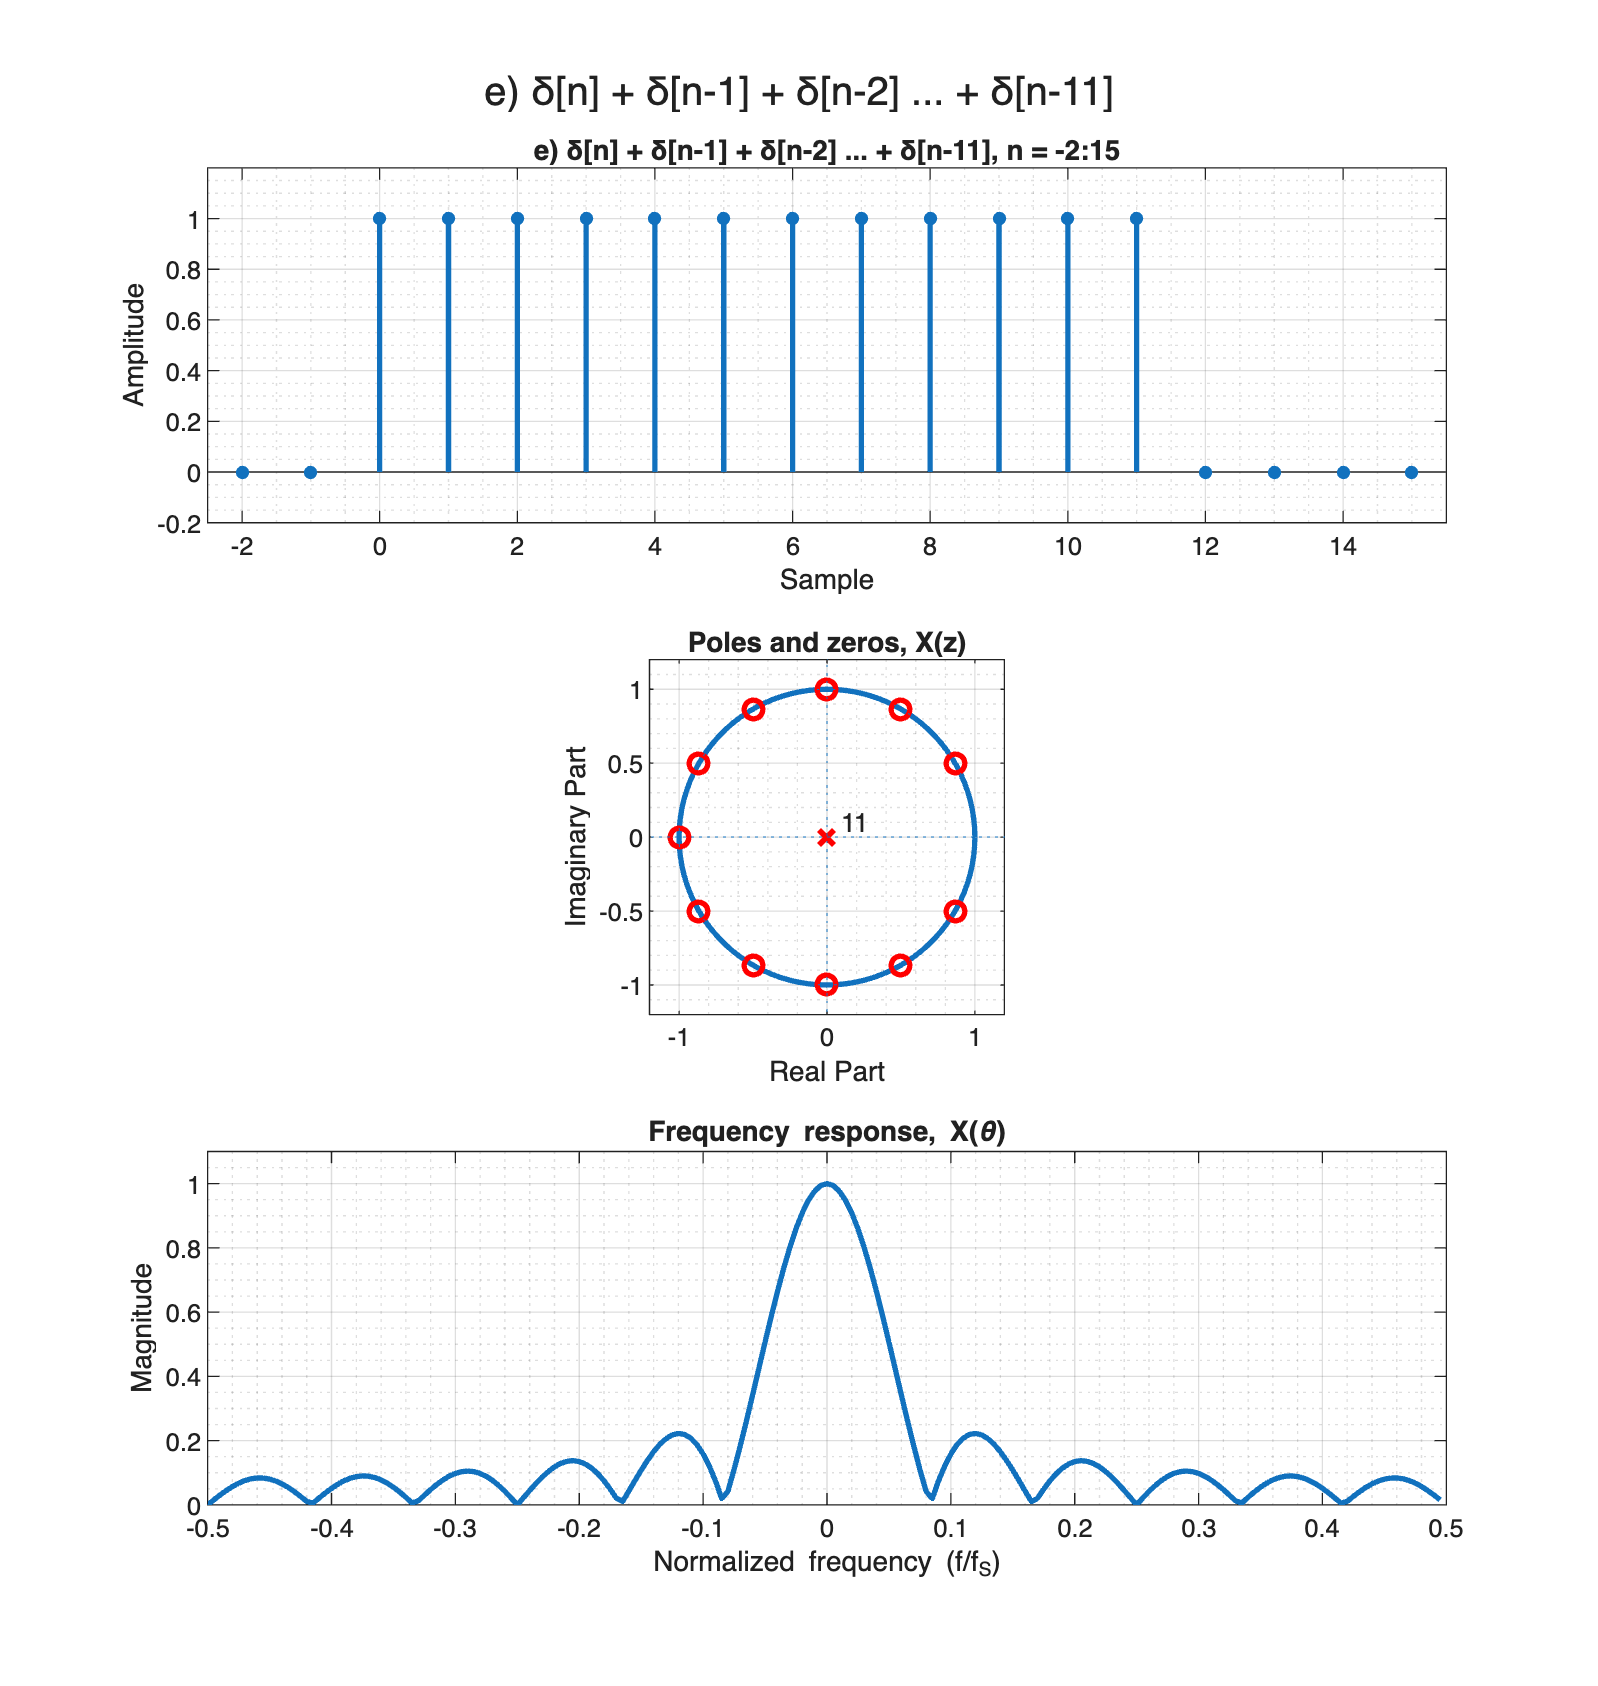

x_e = (n == 0) + (n == 1) + (n == 2) + (n == 3) + (n == 4) + (n == 5) + ...
      (n == 6) + (n == 7) + (n == 8) + (n == 9) + (n == 10) + (n == 11);
% z-transform is (1 + z^-1 + z^-2 + z^-3 + z^-4 + z^-5 ... z^-11)
plot_sig_pz_and_fft(...
  n, x_e, ones(1, 12), 1, "e) δ[n] + δ[n-1] + δ[n-2] ... + δ[n-11]");

### **f) δ[n+1] + δ[n-1]**

z-transform:


$$\[
X(z) = \sum_{n=-\infty}^{\infty} x[n]z^{-n}
\]

\[
X(z) = x[-1]z^{1} + x[1]z^{-1}
\]

\[
X(z) = z + z^{-2}, ROC: z \in \mathbb{C},\ except\ z = 0
\]

or

\[
X(z) = \frac{z^3 + z^0}{z^2}, ROC: z \in \mathbb{C},\ except\ z = 0
\]

This can also be written as

\[
X(z) = z^{1.5}.\frac{z^{1.5} + z^{-1.5}}{z^2} = \frac{1}{z^{0.5}}.({z^{1.5} + z^{-1.5}})
\]$$


Discrete Time Fourier Transform (DTFT):


$$\[
X(\theta) = \left.X(z)\right\vert_{z=e^{j\theta}} = \left.{\frac{1}{z^{0.5}}.({z^{1.5} + z^{-1.5}})}\right\vert_{z=e^{j\theta}
\]

\[
X(\theta) = e^{-j0.5\theta}. ({e^{j1.5\theta} + e^{-j1.5\theta}}) = e^{-j0.5\theta}cos(1.5\theta)}
\]$$


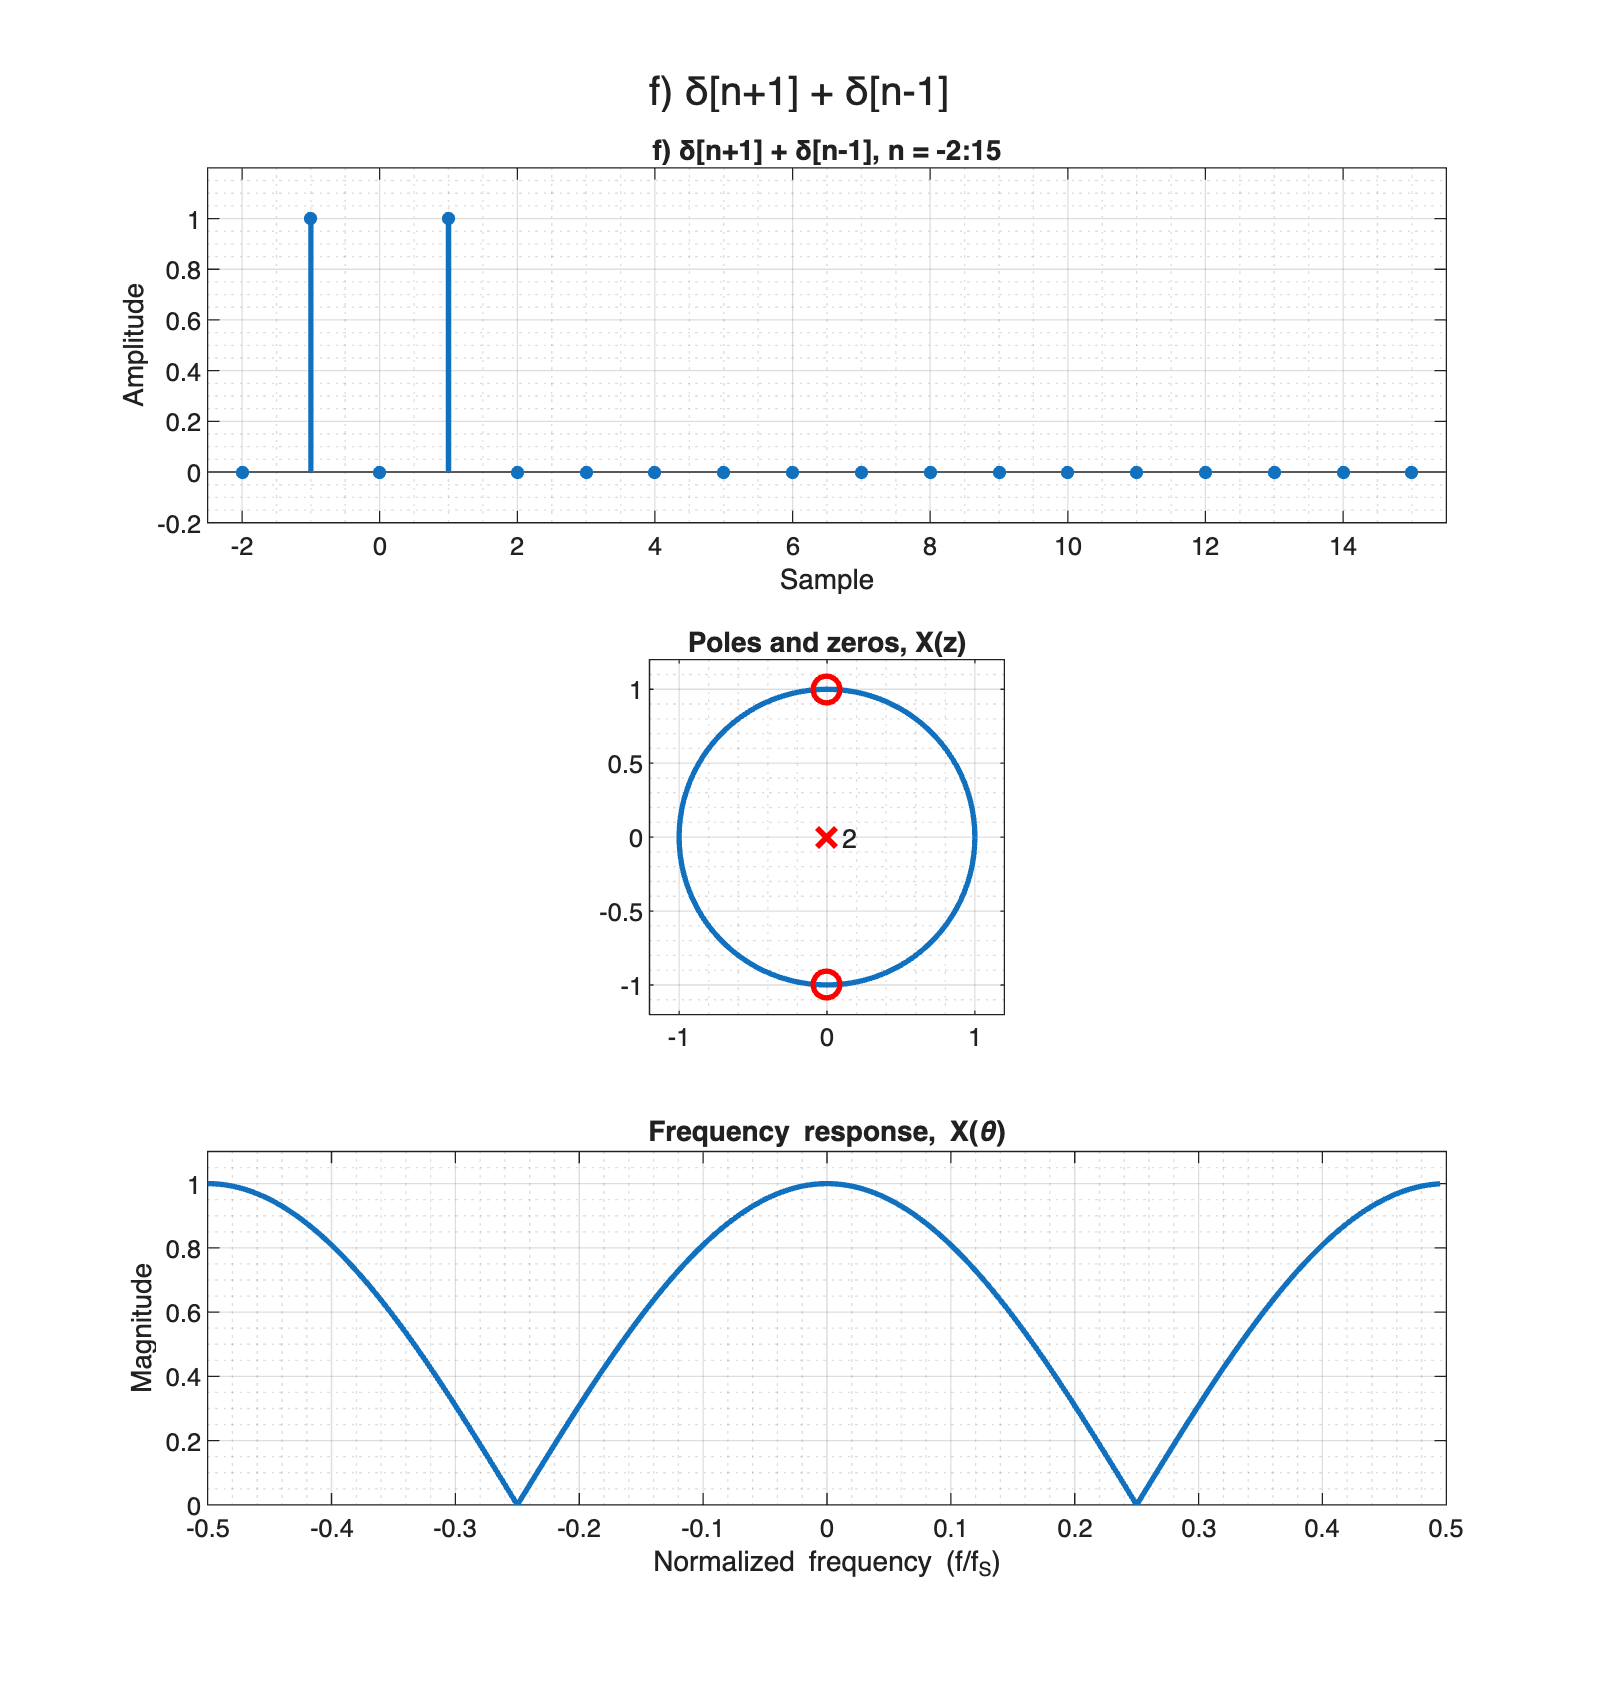

x_f = (n == -1) + (n == 1);
% z-transform is (z + z^-1), or, (1 + z^-2)/z^-1
% Since this is non-causal, Matlab tf2zp routine called within zplane throws an
% error "Denominator must have non-zero leading coefficient". Hence, need
% to do the pole zero plot the hard way.
figure("Position", [0 0 900 950]);
sgtitle("f) δ[n+1] + δ[n-1]");
subplot(3, 1, 1);
stem(n, x_f, "Marker", ".", "LineWidth", 2, "MarkerSize", 15);
xlabel("Sample"); ylabel("Amplitude");
title(sprintf("%s, n = %d:%d", "f) δ[n+1] + δ[n-1]", min(n), max(n)));
grid on; grid minor;
axis on;
axis([min(n) - 0.5, max(n) + 0.5, min(x_f) - 0.2, max(x_f) + 0.2]);

subplot(3, 1, 2);
% Plot the unit circle
plot(exp(1j * 2 * pi * (0 : 0.01 : 1)), "LineWidth", 2);
hold on;
plot(roots([1 0 1]), "ro", "LineWidth",2, "MarkerSize", 10);
plot(0, 0, "rx", "LineWidth", 2, "MarkerSize", 10);
hold off;
text(0.1, 0.0, "2", "FontSize", 10);
title("Poles and zeros, X(z)");
grid on; grid minor;
axis("square");
axis([-1.2 1.2 -1.2 1.2]);

subplot(3, 1, 3);
plot(...
  [-0.5 : 1/200 : 0.5-1/200], fftshift(abs(fft(x_f/sum(x_f), 200))), ...
  "LineWidth", 2);
grid on; grid minor;
axis([-0.5 0.5 0 1.1]);
title("Frequency response, X(\theta)");
xlabel("Normalized frequency (f/f_S)"); ylabel("Magnitude");

### **g) δ[n] + δ[n-1] + δ[n-2] + ... (non-terminating)**

z-transform:


$$\[
X(z) = \sum_{n=-\infty}^{\infty} x[n]z^{-n}
\]

\[
X(z) = \sum_{n=0}^{\infty} z^{-n}
\]

The above series will converge for |z| > 1, and the resulting geometric progression's sum would be
\[
X(z) = \frac{1}{1 - z^{-1}}, ROC: |z| > 1
\]

or

\[
X(z) = \frac{z^1}{z^1 - z^0}, ROC: |z| > 1
\]$$


DTFT does not exist for this signal, since it is **not** absolutely summable, i.e. 


$$\[
\sum_{n=-\infty}^{\infty} |x[n]| < {\infty}
\]
$$
 

does not hold.

This is also indicated by the ROC not containing the unit circle.

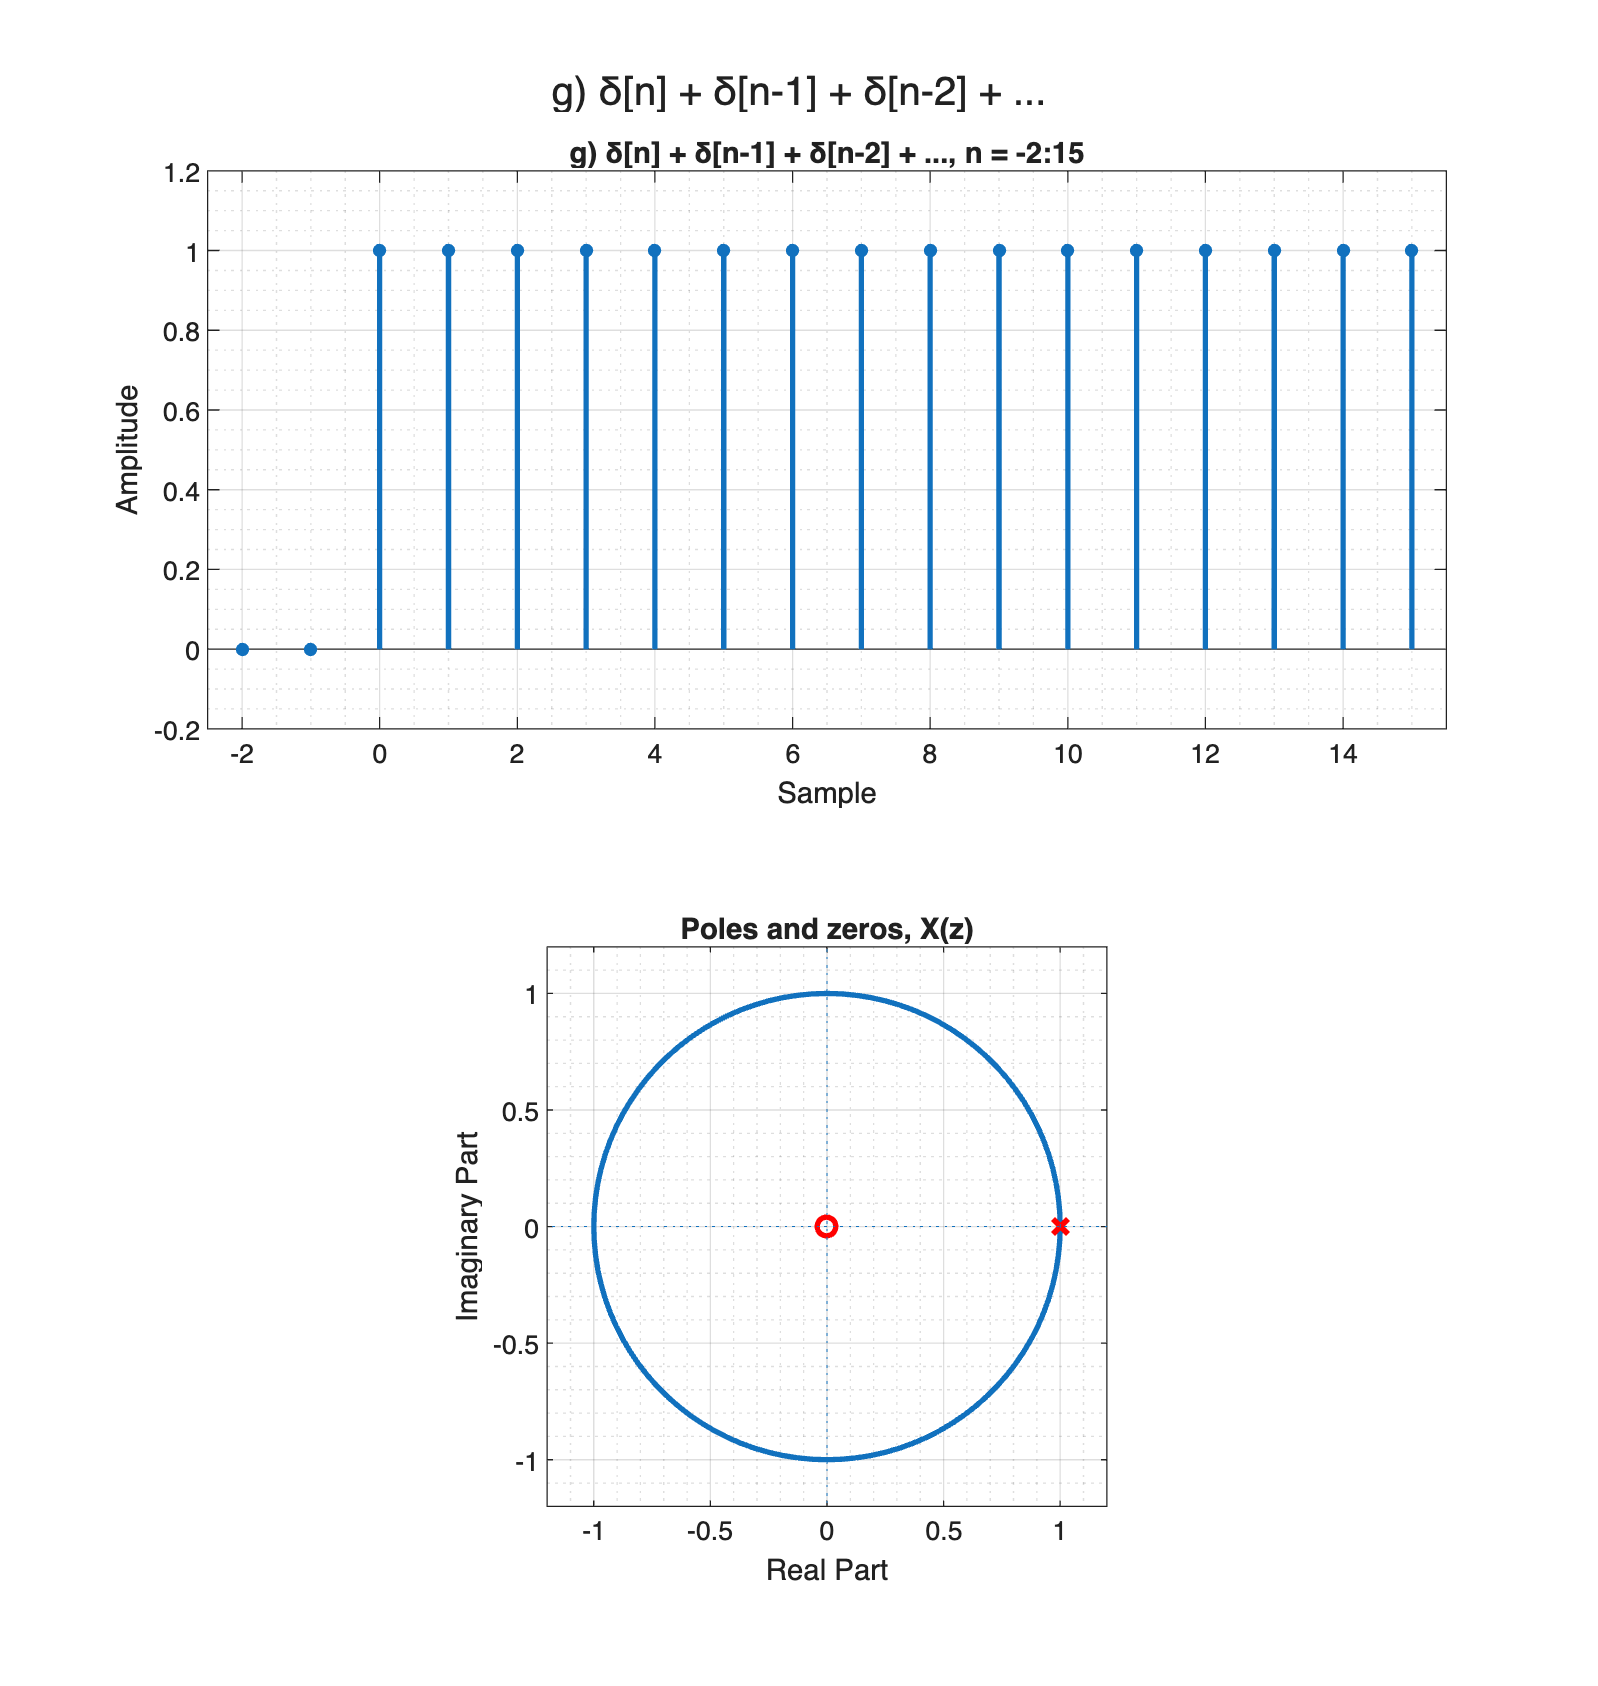

x_g = (n >= 0);
% z-transform is (1 + z^-1 + z^-2 + z^-3 + z^-4 + z^-5 ...), or,
% 1/(1 - z^-1) for ROC |z| > 1
plot_sig_pz_and_fft(...
  n, x_g, 1, [1 -1], "g) δ[n] + δ[n-1] + δ[n-2] + ...", false);

### **h) δ[n] + (0.9)δ[n-1] + (0.9^2)δ[n-2] + ... (non-terminating)**

z-transform:


$$\[
X(z) = \sum_{n=-\infty}^{\infty} x[n]z^{-n}
\]

\[
X(z) = \sum_{n=0}^{\infty} (0.9)^{n}z^{-n}
\]

The above series will converge for |z| > 0.9, and the resulting geometric progression's sum would be
\[
X(z) = \frac{1}{1 - 0.9z^{-1}}, ROC: |z| > 0.9
\]

or

\[
X(z) = \frac{z^1}{z^1 - 0.9z^{0}}, ROC: |z| > 0.9
\]$$


Discrete Time Fourier Transform (DTFT):


$$\[
X(\theta) = \left.X(z)\right\vert_{z=e^{j\theta}} = \left.{\frac{1}{1 - 0.9z^{-1}}}\right\vert_{z=e^{j\theta}
\]

\[
X(\theta) = \frac{1}{1 - 0.9e^{-j\theta}}
\]$$


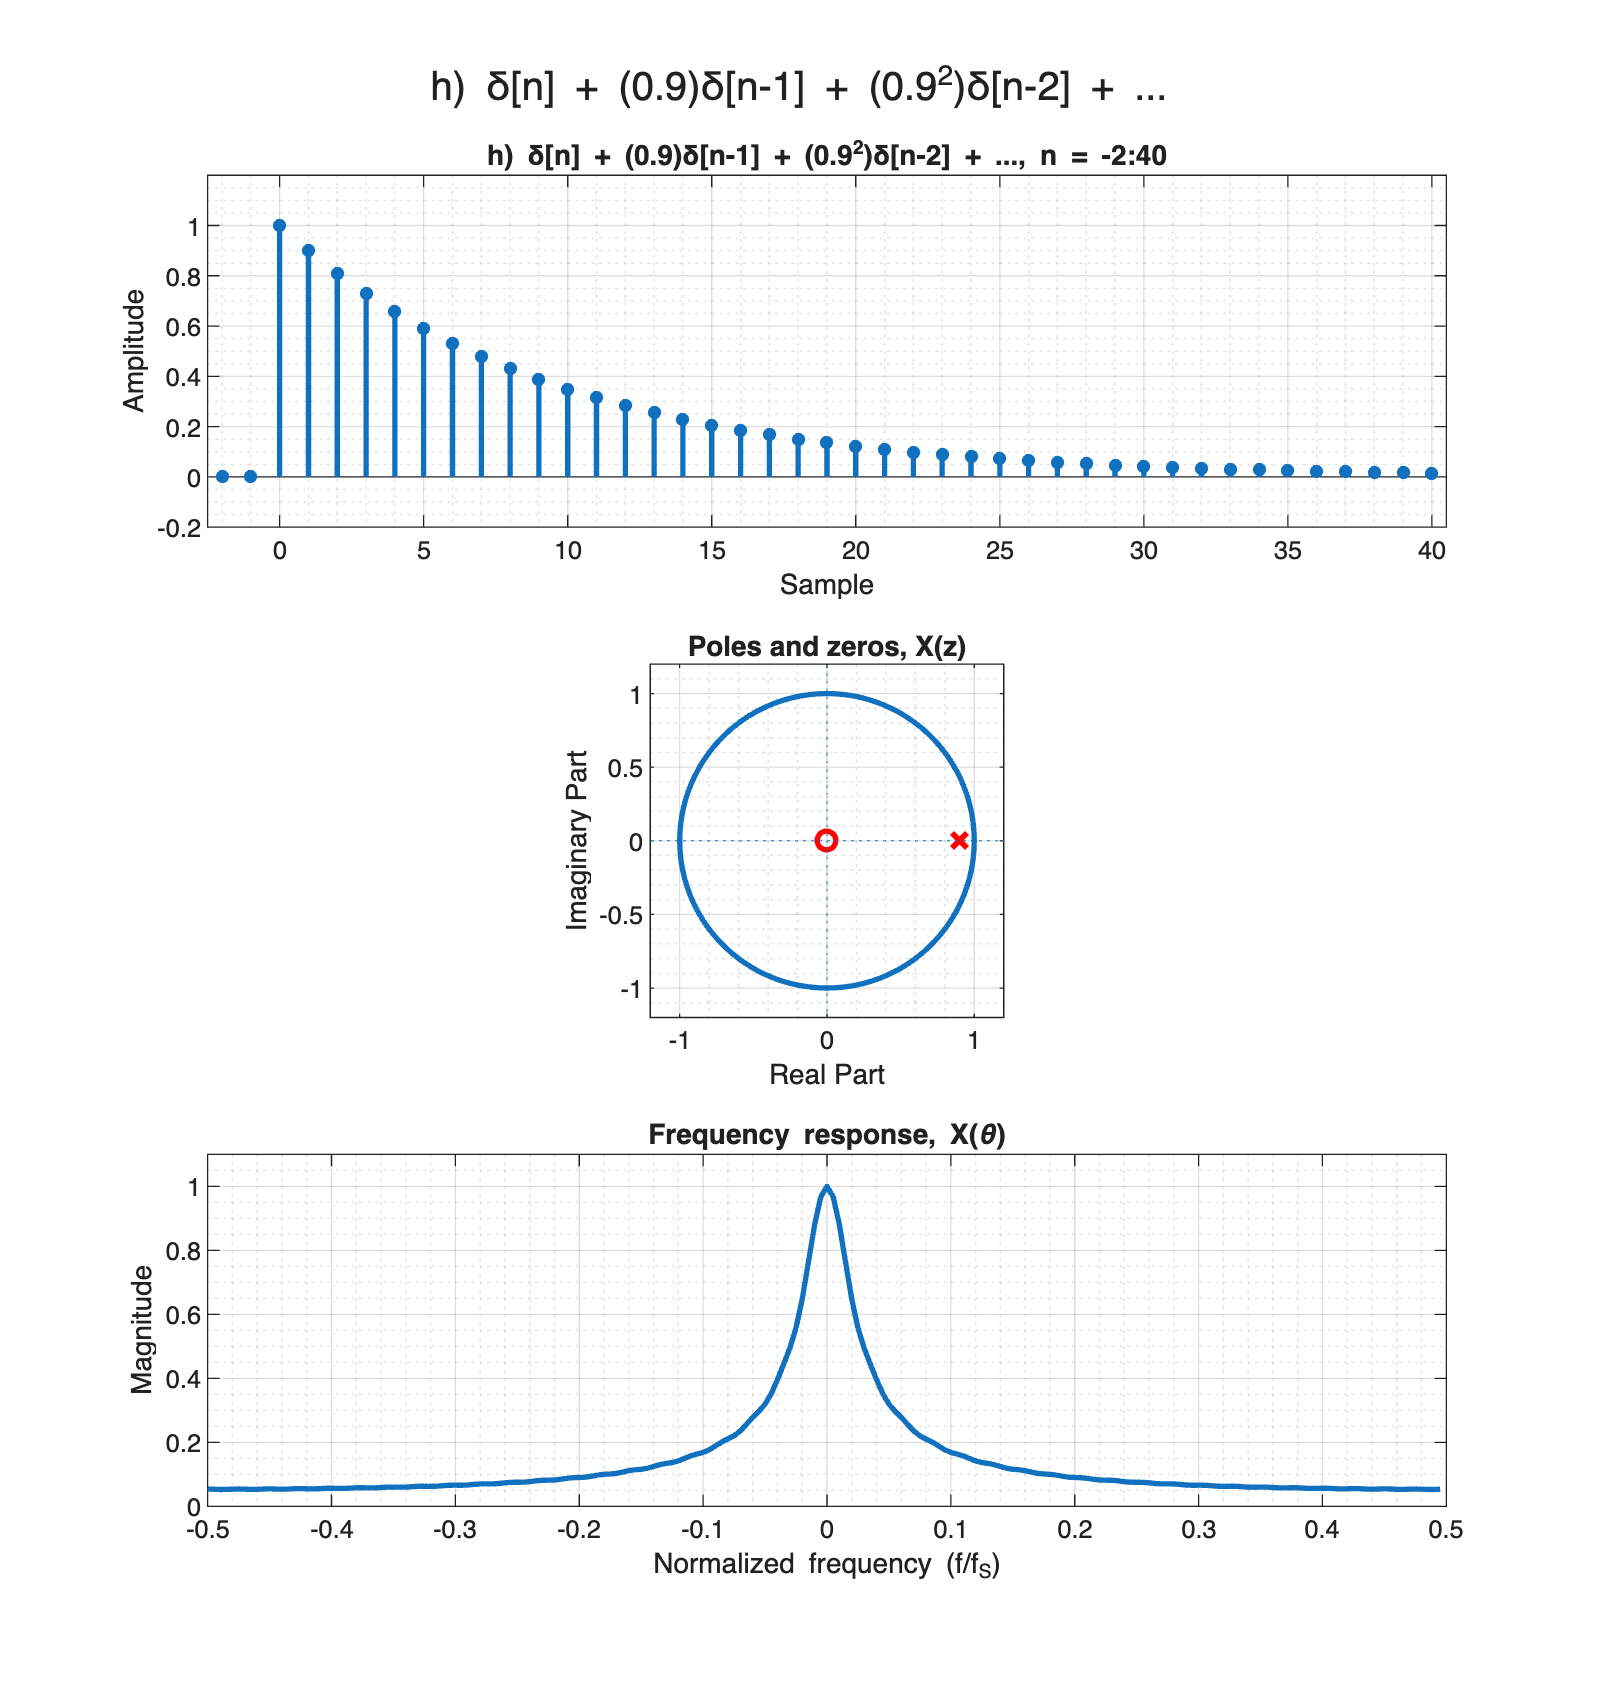

n = [-2 : 40]; % Increasing the sample size to show the amplitude attenuation

a = 0.9;
x_h = (a.^n) .* (n >= 0);
% z-transform is (1 + z^-1/a + z^-2/a^2 + z^-3/a^3 + ...), or,
% 1/(1 - a*z^-1) for ROC |z| > |a|
plot_sig_pz_and_fft(...
  n, x_h, 1, [1 -a], "h) δ[n] + (0.9)δ[n-1] + (0.9^2)δ[n-2] + ...");

### **i) δ[n] + e^{j2π/10}δ[n-1] + e^{2j2π/10}δ[n-2] + ... (non-terminating)**

z-transform:


$$\[
X(z) = \sum_{n=-\infty}^{\infty} x[n]z^{-n}
\]

\[
X(z) = \sum_{n=0}^{\infty} (e^{j \frac{2 \pi n}{10}})z^{-n}
\]

The above series will converge for |z| > 1, and the resulting geometric progression's sum would be
\[
X(z) = \frac{1}{1 - (e^{j \frac{2 \pi}{10}})z^{-1}}, ROC: |z| > 1
\]

or

\[
X(z) = \frac{z^1}{z^1 - (e^{j \frac{2 \pi}{10}})z^0}, ROC: |z| > 1
\]
$$


DTFT does not exist for this signal, since it is **not** absolutely summable, i.e. 


$$\[
\sum_{n=-\infty}^{\infty} |x[n]| < {\infty}
\]
$$
 

does not hold.

This is also indicated by the ROC not containing the unit circle.

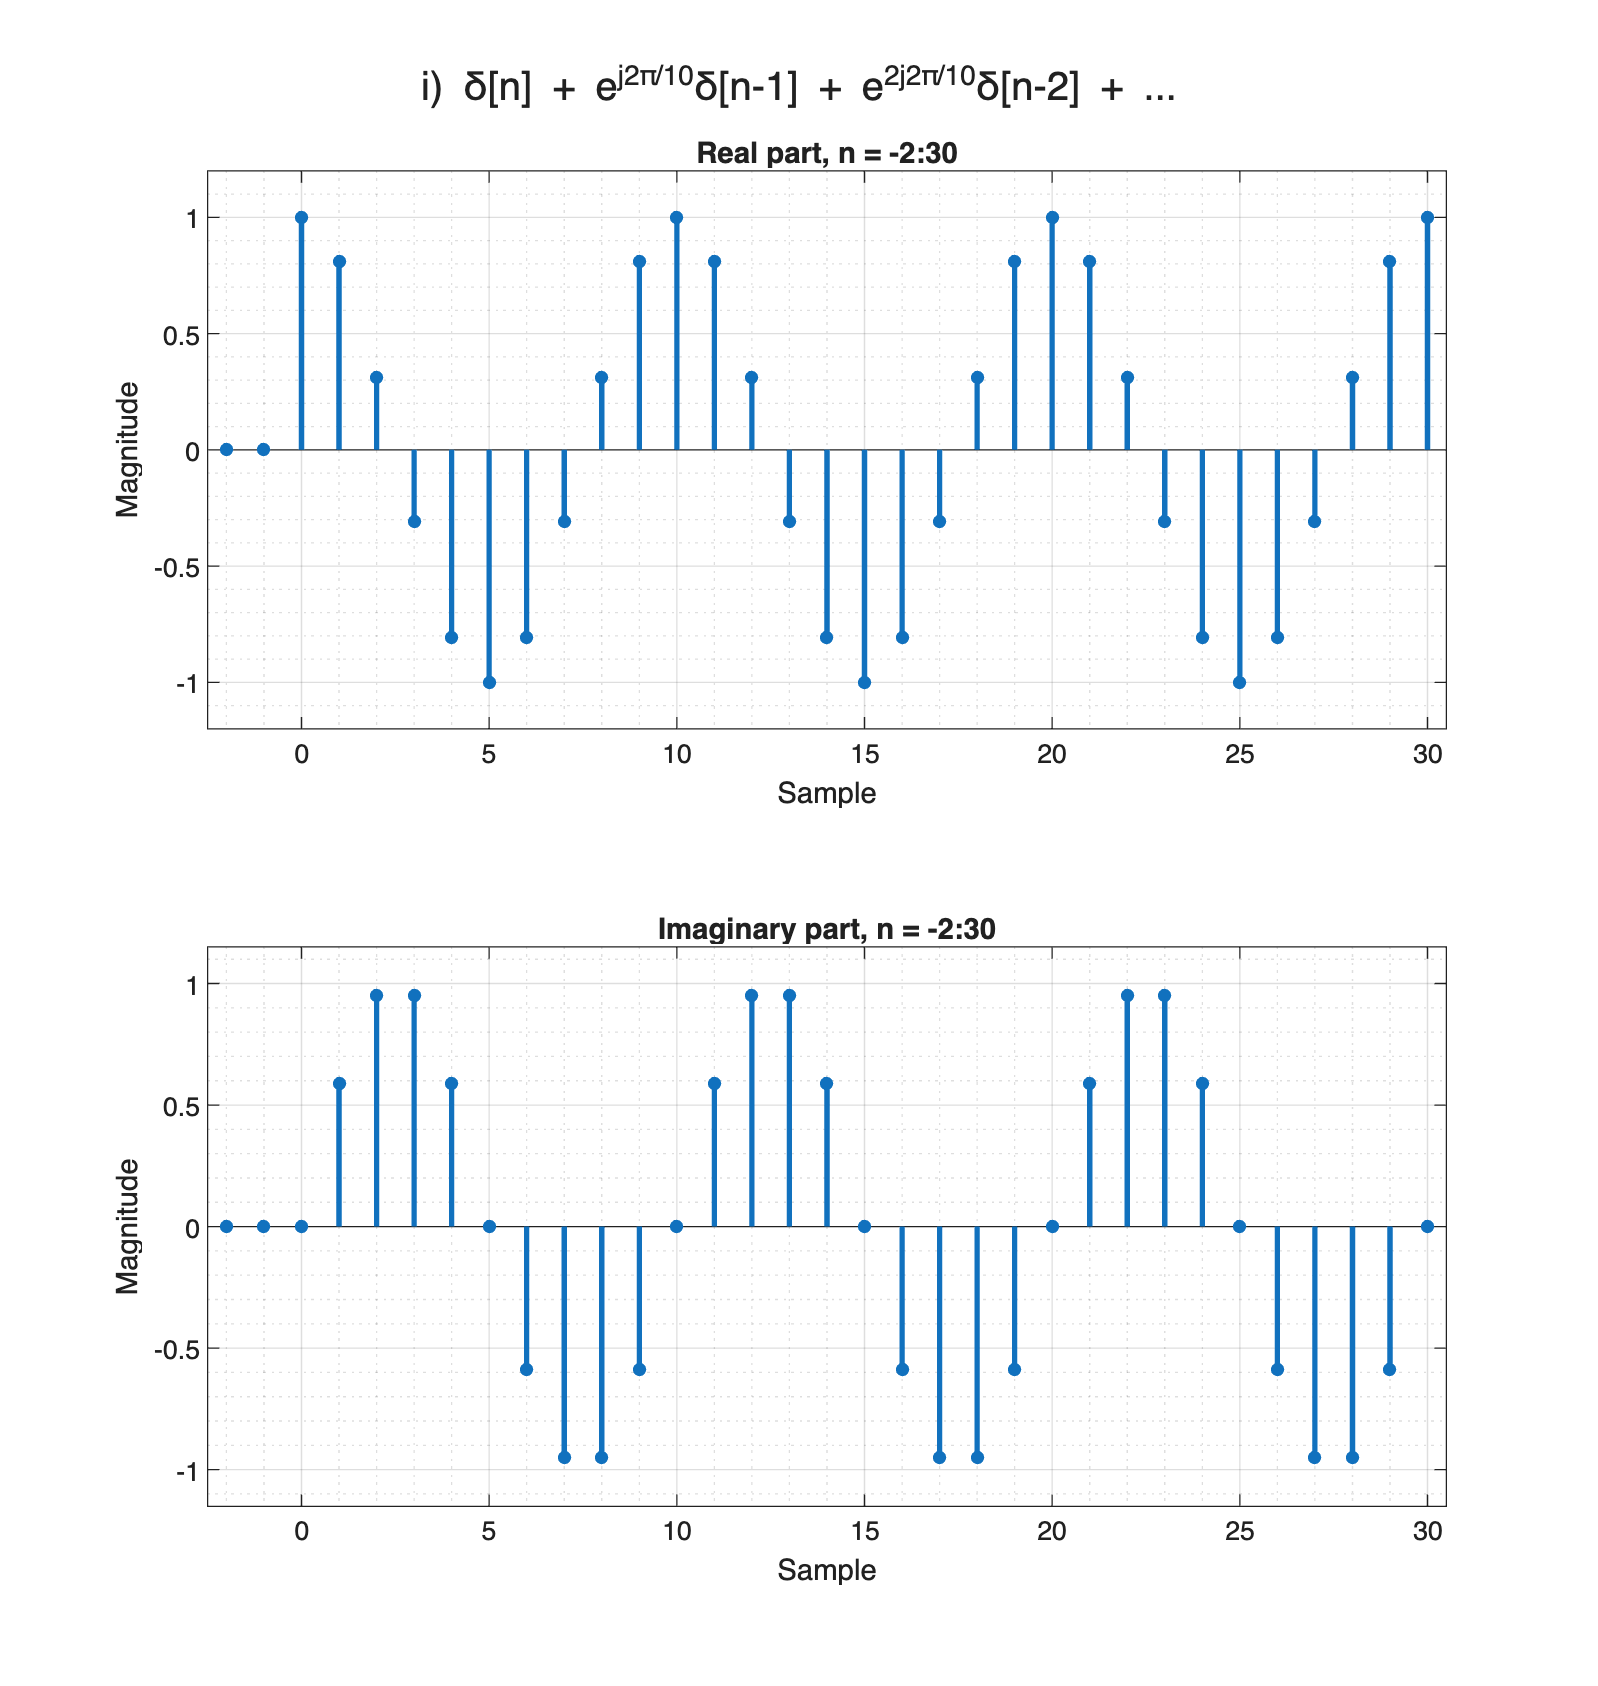

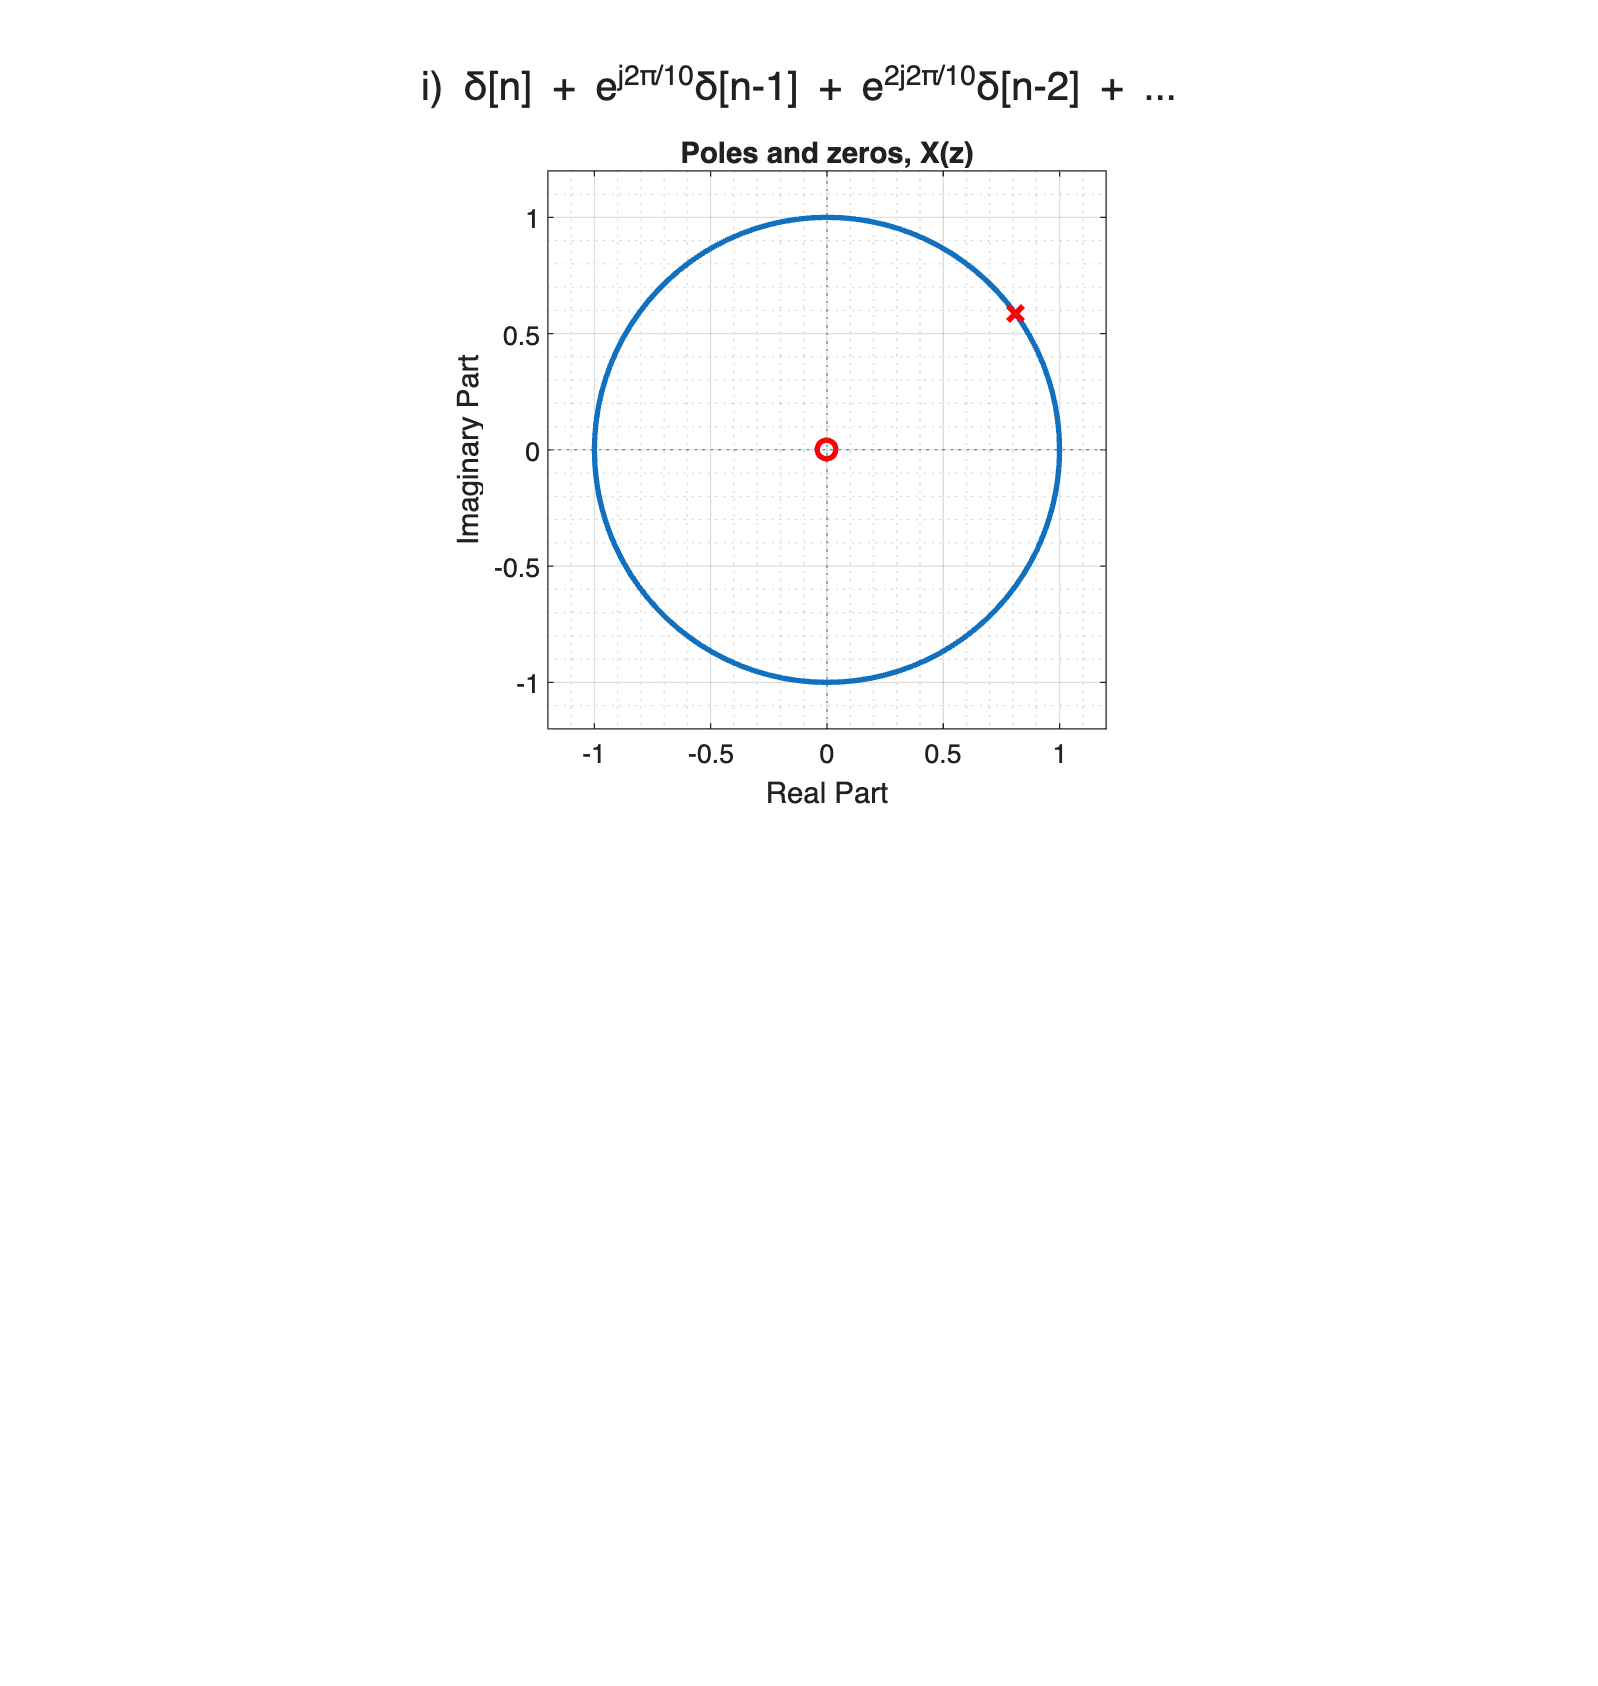

n = [-2 : 30];

a = exp(1i * 2 * pi / 10);
x_i = (a.^n) .* (n >= 0);
% z-transform is (1 + z^-1/a + z^-2/a^2 + z^-3/a^3 + ...), or,
% 1/(1 - a*z^-1) for ROC |z| > |a|
plot_cmplx_sig_pz_and_fft(...
  n, x_i, 1, [1 -a], ...
  "i) δ[n] + e^{j2π/10}δ[n-1] + e^{2j2π/10}δ[n-2] + ...", false);

### **j) δ[n] + 0.9e^{j2π/10}δ[n-1] + (0.9e^{j2π/10})^2δ[n-2] + ... (non-terminating)**

z-transform:


$$\[
X(z) = \sum_{n=-\infty}^{\infty} x[n]z^{-n}
\]

\[
X(z) = \sum_{n=0}^{\infty} (0.9e^{j \frac{2 \pi}{10}})^{n}z^{-n}
\]

The above series will converge for |z| > 0.9
\[
X(z) = \frac{1}{1 - (0.9e^{j \frac{2 \pi}{10}})z^{-1}}, ROC: |z| > 0.9
\]
$$


Discrete Time Fourier Transform (DTFT):


$$\[
X(\theta) = \left.X(z)\right\vert_{z=e^{j\theta}} = \left.\frac{1}{1 - (0.9e^{j \frac{2 \pi}{10}})z^{-1}}\right\vert_{z=e^{j\theta}
\]

\[
X(\theta) = \frac{1}{1 - (0.9e^{j \frac{2 \pi}{10}})e^{-j\theta}} = \frac{1}{1 - 0.9e^{-j (\theta - \frac{2 \pi}{10})}}
\]$$


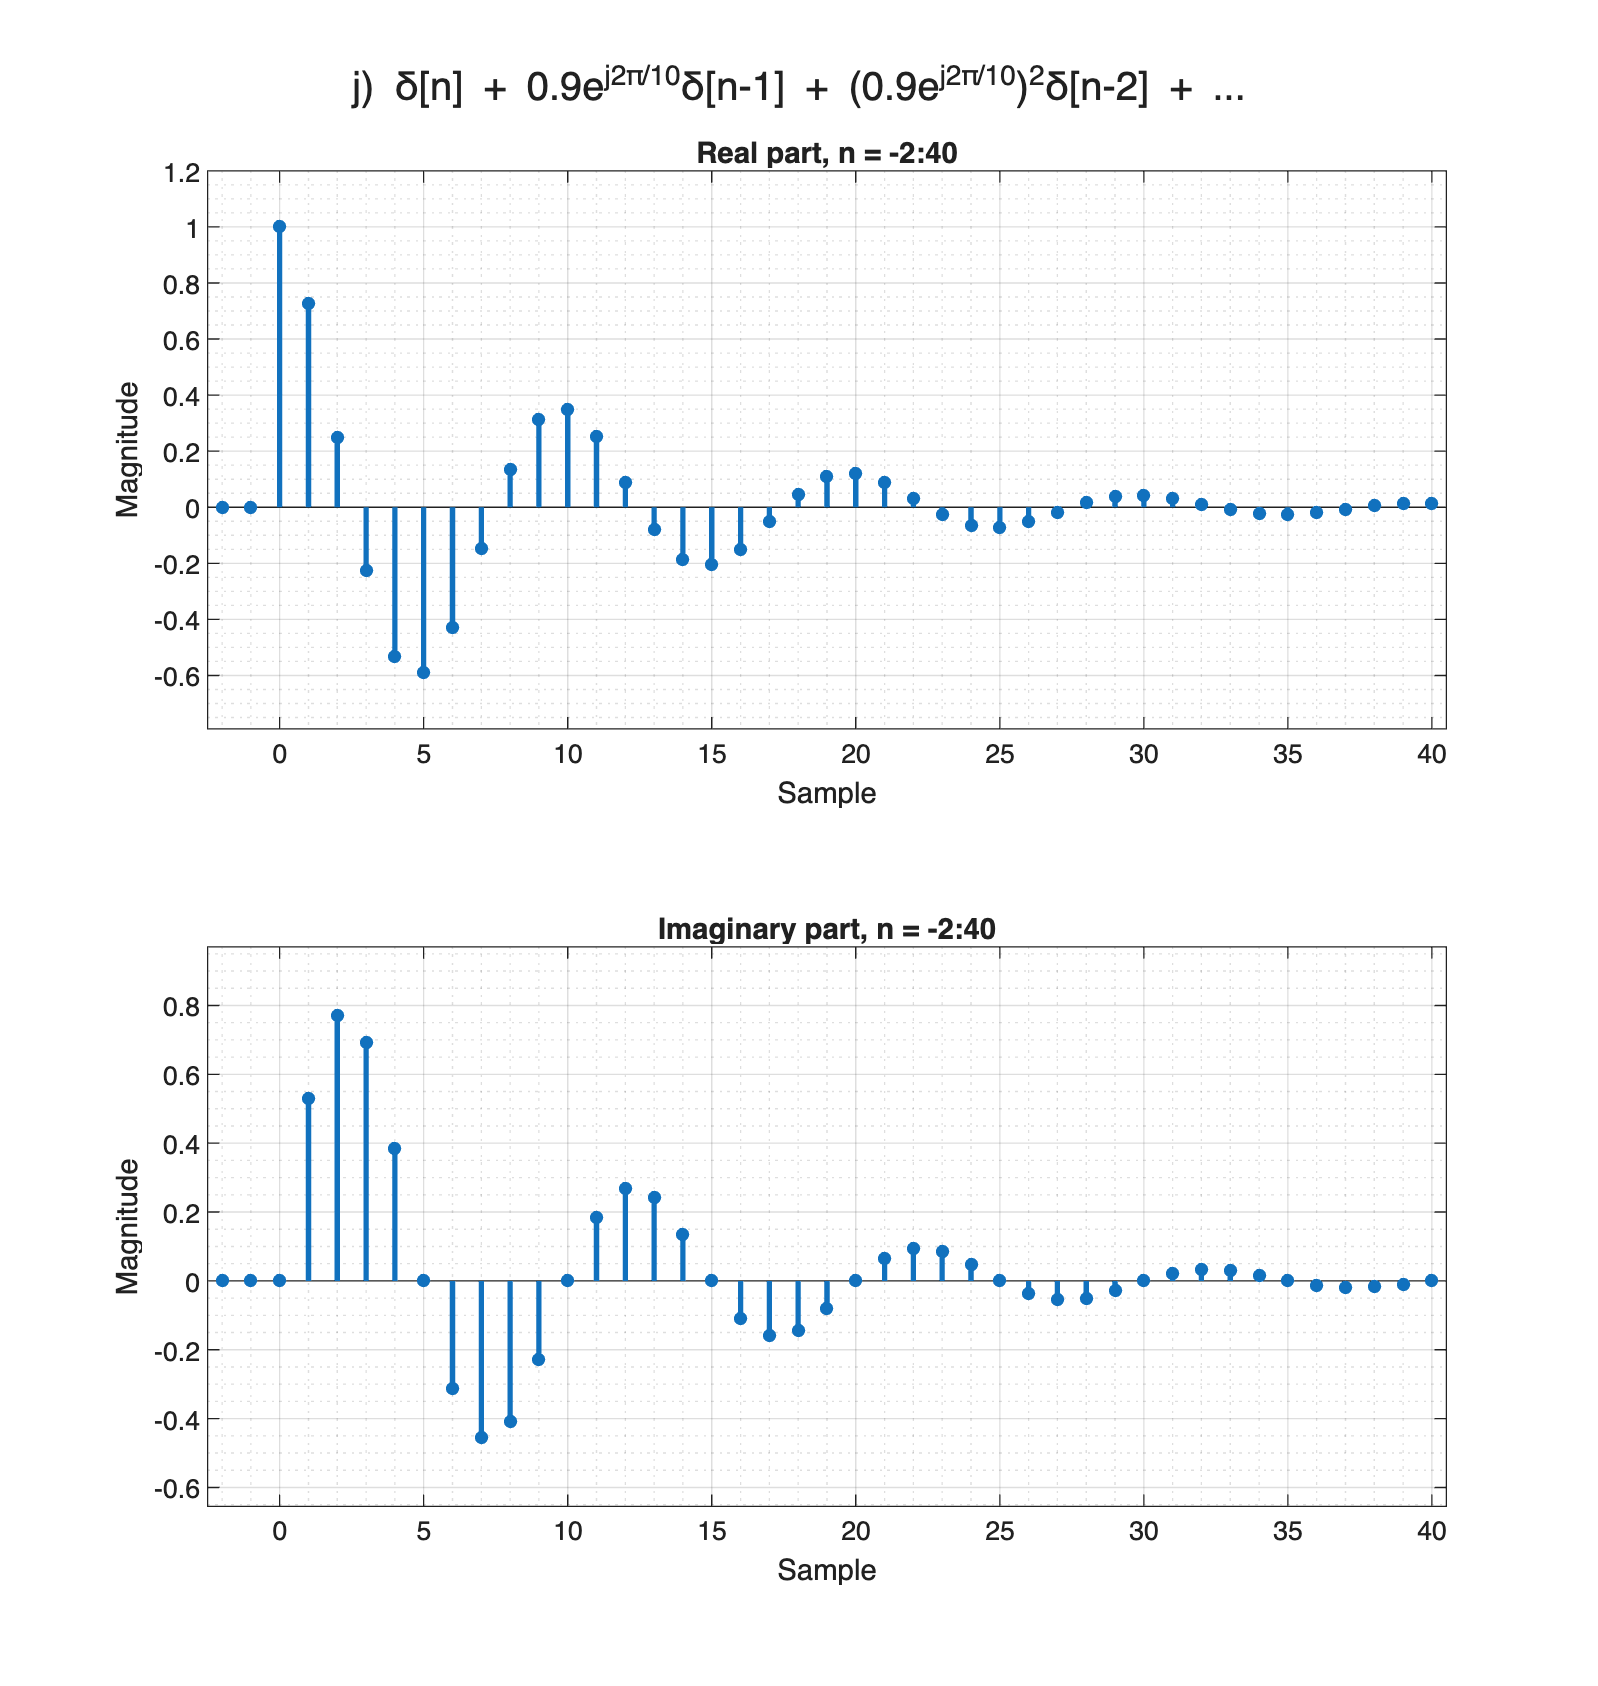

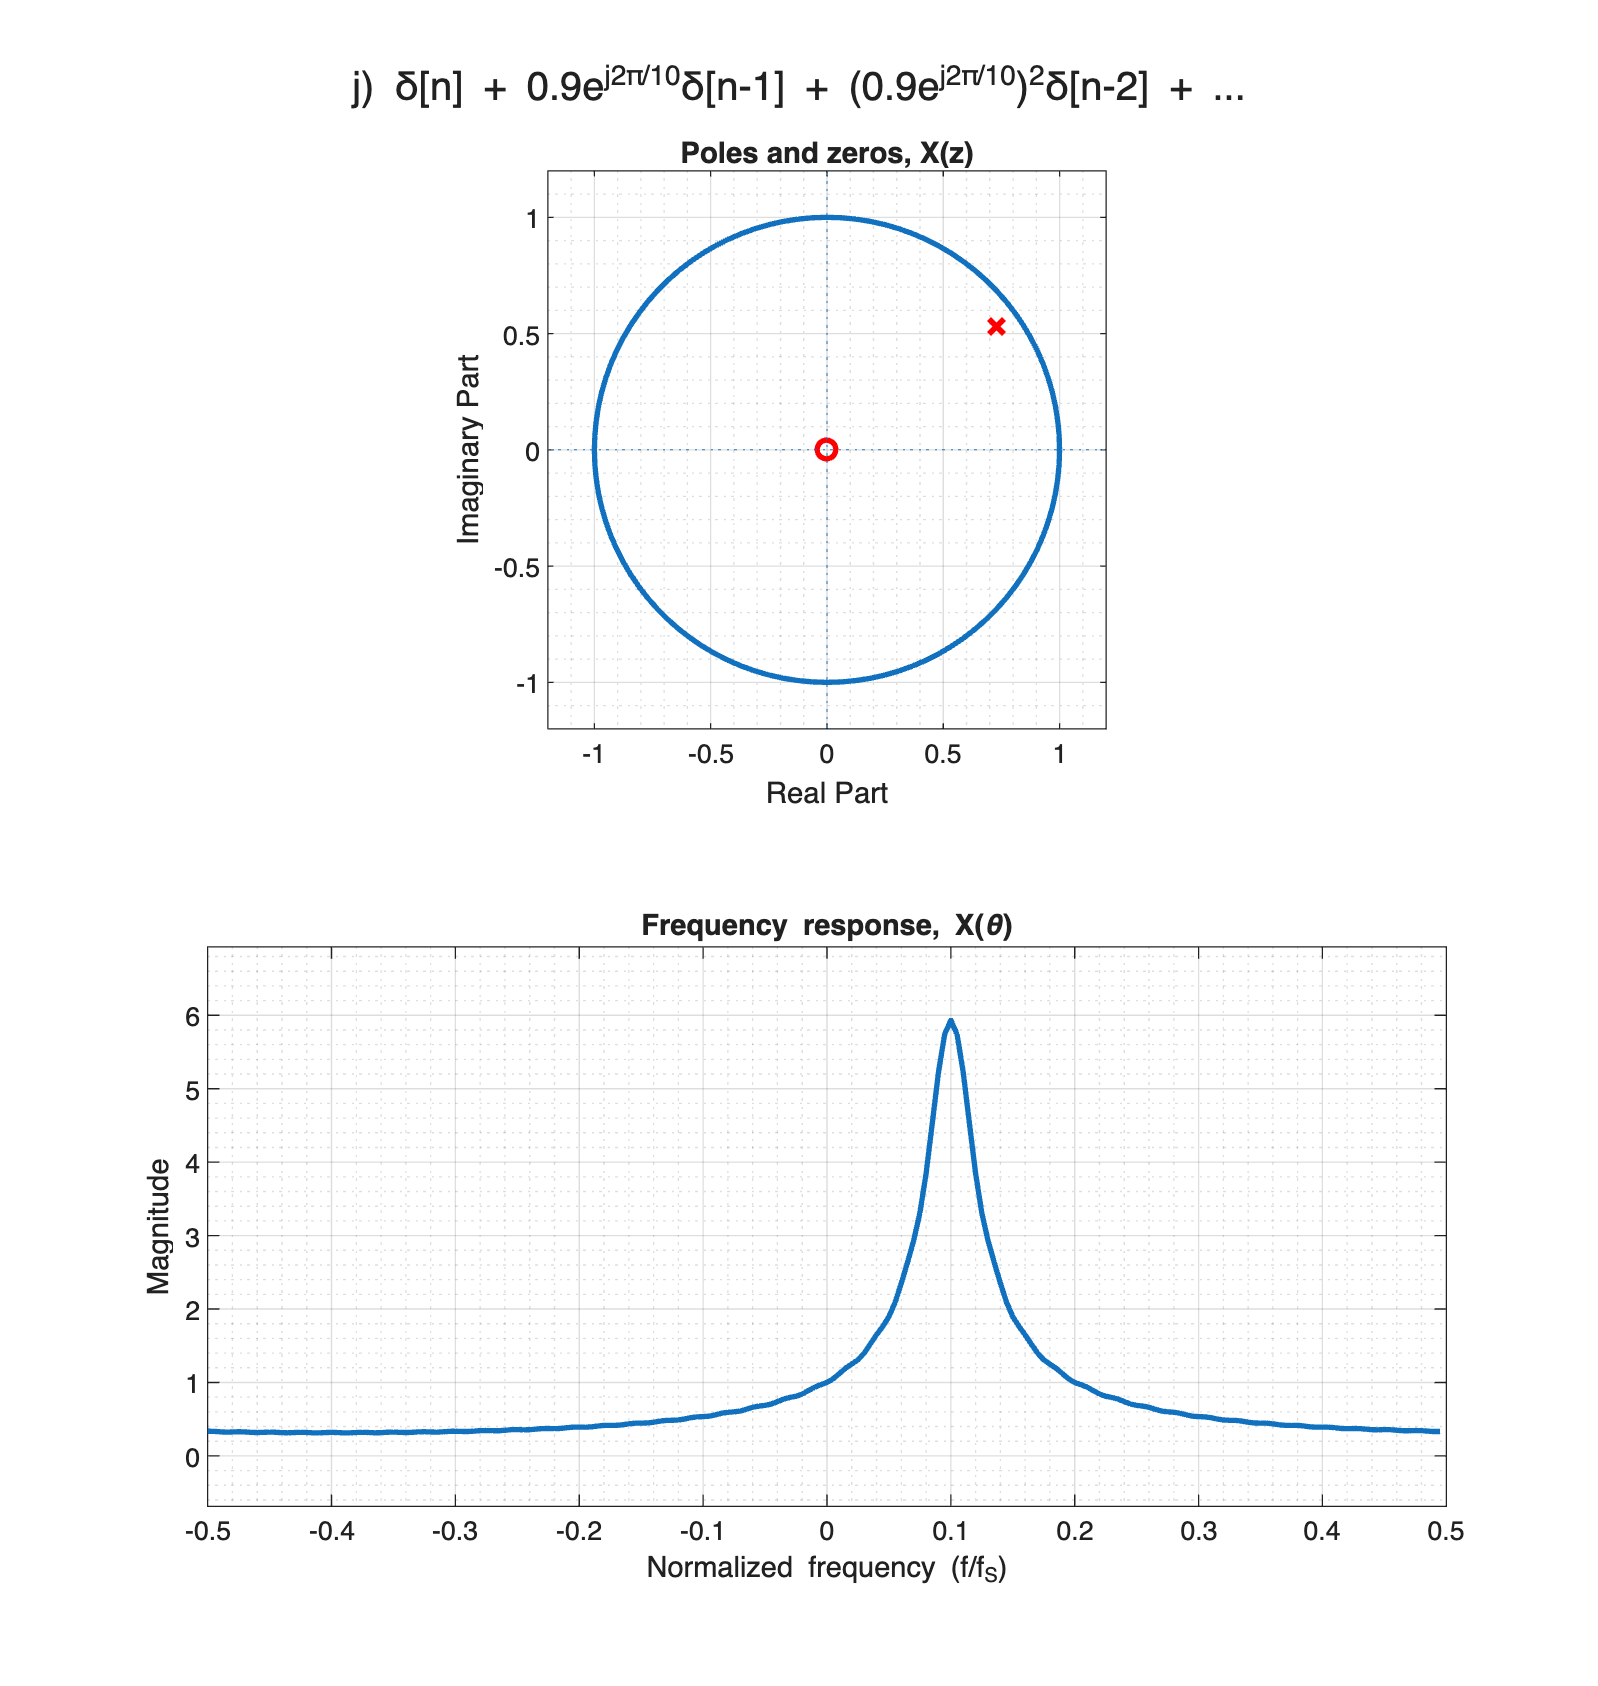

n = [-2 : 40]; % Increasing the sample size to show the amplitude attenuation

a = 0.9 * exp(1i * 2 * pi / 10);
x_j = (a.^n) .* (n >= 0);
% z-transform is (1 + z^-1/a + z^-2/a^2 + z^-3/a^3 + ...), or,
% 1/(1 - a*z^-1) for ROC |z| > |a|
plot_cmplx_sig_pz_and_fft(...
  n, x_j, 1, [1 -a], ...
  "j) δ[n] + 0.9e^{j2π/10}δ[n-1] + (0.9e^{j2π/10})^2δ[n-2] + ...");